# Coursework 2

Please submit all question regarding this coursework in the Coursework 2 section forum in Q&A part in the Moodle page. ***No**** code should be submitted or discussed in the Forum.*

**Marks:** 25% of module mark. Marking rubric is on Moodle. Marks and feedback will be provided 15 working days after the submission deadline; each student will receive an individual copy of the marking rubric posted on Moodle by email. If required, further individual feedback is then available by requesting a one-to-one meeting.

**Submission: **MATLAB live script (.mlx). To be submitted via Moodle.

**Deadline: **Wednesday 6 May 2020 at 3pm.

**Files: **For Question 2 and 3, you will need the accompanying dataset in the zipped-folder "handwritten_number_rgb". 

**Note about copying code: **We may use MOSS ([http://theory.stanford.edu/~aiken/moss/](http://theory.stanford.edu/~aiken/moss/)) to check for similarity between pieces of code - both with other students and with code available online.  Please WRITE YOUR OWN CODE and do not just copy from online examples - you will get zero if you are found doing this.

### Instructions:

- All answers must be written in this file.

- For your coursework submission, you will **submit a single mlx file** which contains the questions and the answers (descriptive answer and codes). 

- Local functions should be written at the end of the mlx files 

- In addition to the code to produce results and plots, **any plot must be embedded within the mlx file as image**. It can be done by insert > image. 

- This mlx must be self-contained. That is, **this script will run with "no change", except for a line in question 2 and 3 which will be modified by me to refer to my own testing directory.** 

### Matlab prerequisite:

- Matlab Deep-Learning Toolbox 

- Matlab Image-Processing Toolbox

- *[WRITE HERE IF YOUR ANSWER REQUIRE ADDITIONAL TOOLBOX]*

## Question 0 - Back-Propagation (BP) Blackbox Engine [10%]

For this question, write a function which implement back-propagation algorithm for a single hidden layer feedforward ANN. This function should be "flexible" and behave just as a black-box engine. 

Describe the function interface! (consider this as your code documentation)

*Hint: Read all the question in this coursework before working on this task. Think carefully how my function's interface will looks like, make sure it will be flexible to be use throughout this coursework. Write the local function in the bottom of this file.*  

I mainly use the back-progation algorihm provided in the lab. In addition to core algorithm, I added an extra output which gives desired task result and an extra input variable that define the task ( forced_comment).

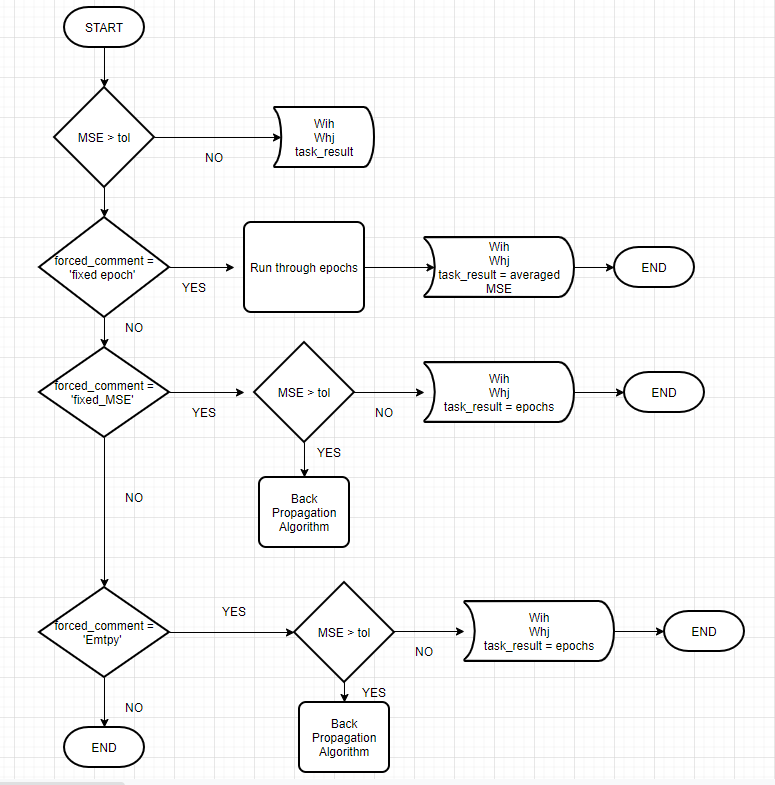

Basically, the backprogation algorithm run throush MSE > tolerance. However, forced_comment variable breaks this loop and give the desired task result. The other method could be extract the core back-propagation algorithm from the function and call this according to the task. 

forced_comment = 'fixed_epoch' -----> it returns the MSE for fixed epoch number ( tolerance should be arrange lower than normal) 

forced_comment = 'fixed_MSE' -------> it returns the number of epoch that achieved desired MSE

forced_comment = 'empty' -----------> it allows to train the data according to desired MSE. 

I also added  an extra error function that gives infinite loop error and ask change the tolerance. I counted the how many times function restart the epochs, if it restart the epochs 20 times, it gives an error and break the function. 

## Question 1 - Artificial Neural Network Application for Iris Flower Classification [30%]

In this question, you will use the back-propagation (BP) blackbox function implemented in Q0, to perform classification of Iris dataset.

Matlab has Iris flower dataset:

clc;
close all;
clear variables;
[A,D] = iris_dataset; 

    **ANALYSIS OF DATA**                          

                                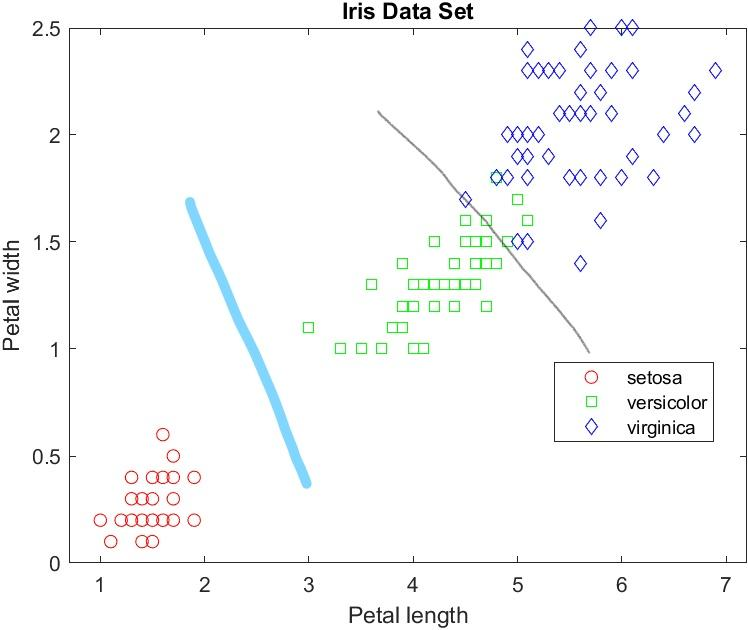

                               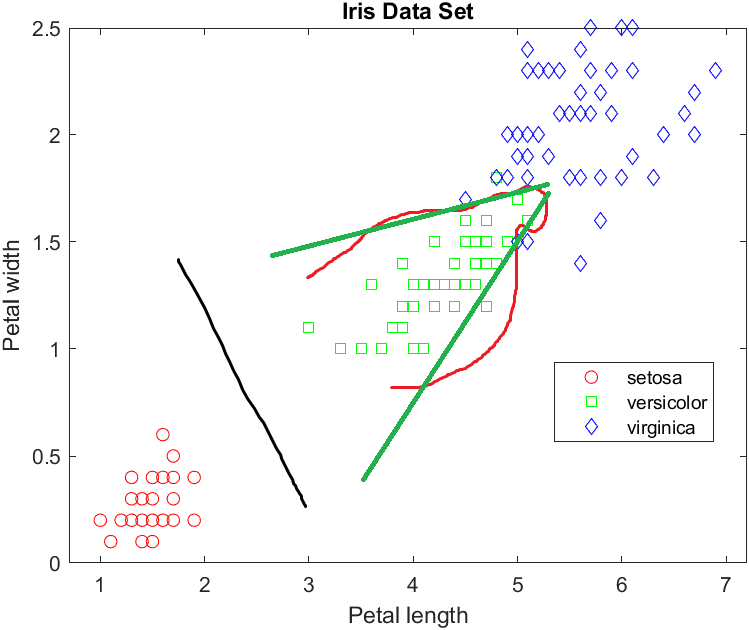

In artifical neural networks, hidden layers are required if the data is non-linearly seperable. If we look the first figure at the above, we can see that the data can be seperated linearly. However, to imrpove the accuracy we can use multiple lines which will be perceptrons in hidden layers. We have 150 data points and each class have same contribution to the data set. Therefore, a single line is expected to get the accuracy 66%. This means a single hidden layer with a single neuron will not satisfy desired accuracy. On the other hand, a single hidden layer with 2 neurons might get an accuracy above 85%. The second figure shows that the decision boundries, as it is shown that we might get better results by adjusting neurons in the hidden layer. 

**SUFFICENT EFFICENY CAN BE ACHIEVED ; **

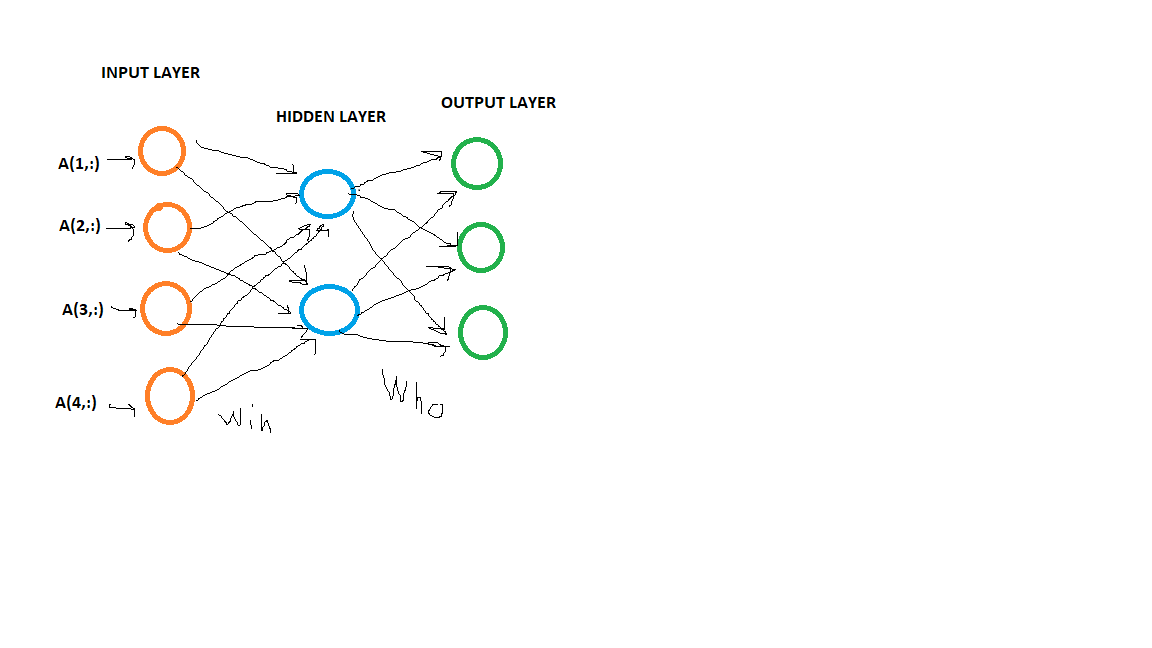

### Task 1(a) 

For a fixed value of allowed maximum number of epoch, plot the Mean Squared Error (MSE) achieved for different number of neurons in the hidden layer. 

Describe your finding!

*Hint: *

*(1) Justify your decision why you pick a certain value of  "allowed maximum number of epoch"!*

*(2) Is it wise to just do one realisation for each number of neuron parameter? Will it be representative? May be I need to do several realisations for each number of neuron parameters then take the means of the MSE over all realisations.  *

**(1) **In this task, we will determine the allowed maximum number of epoch. The first concern should be adequate number of epochs was chosen. In addition to this, we should remember that when the number of hidden neurons increased , more epochs will be needed at the beginning to reach desired tolerance. We also consider overfitting and  computing time. For instance, if we choose 3000 epochs, computing time will be much more than 150 epochs and there will no significant change in accuracy. Epochs also may cause overfitting, that means we may not see significant changes after some point. In this task, I arranged my epochs to see overall performance..

**(2)** In back propagation algorithm guess matrix is changing with number of hidden neurons due to fact that more hidden layers will be end with more connections which means more weights.  We initialize our matrixes using random numbers therefore the bigger matrixes will need time to reduce this randomness effect. In other words,  we initilize our guess matrixes with random numbers, and when we increase the number of neurons weight matrix dimensions also increased and therefore small epoch number can not eliminate the randomness of the initilaze matrix and it gives much higher MSE.To sum up, increased number of hidden neuron needs more epoch to adjust its weights.. We need to average the MSE due to randomness effect. 

I also want to mention relationship between epoch and learning rate. This is the other factor that can effect epoch number. In this task, I normalized my data set due to allow much higher learning rate. We can explain that , we want to reach the point 20 steps away from us. If we move just 1 step it will take 20 movements to reach the point, on the other hand if we move 10 steps , this will take just take 2 movements to reach to the point. However, these considerations can not allow to find optimum epoch number, therefore we need to do experiements for each case to find that.

task_limit = 30;
lambda = 1; 
eta = 1.2;         % learning rate   
alpha = 0.8;       % momentum
tol = 0.0001;      % error tollerance (In this task we need to adjust very small number tolerance to allow epochs run)
random_style = 'fixed_random'

random_style = 'fixed_random'

[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(A,D,random_style);
[training_set,validation_set] = normalizationOfMatrix(training_set,validation_set);
forced_comment = 'fixed_epoch';
hiddenMatrix = zeros(1,task_limit);
max_num_hidden_neuron = 0;
max_epoch = 350;

for num_hidden_neuron = 1:task_limit
selected_hidden_neurons_temp = 0;
[Wih_guess,Whj_guess] = guessWeightMatrixs(training_set,desired_test_set,num_hidden_neuron);    
[Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(  training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
hiddenMatrix(1,num_hidden_neuron) =task_result ; 
max_num_hidden_neuron = num_hidden_neuron;
end

Number of Neurons in Hidden Layer : 1 | Averaged MSE : 7.049e-02 
 | Achieved MSE : 6.391e-02 
Number of Neurons in Hidden Layer : 2 | Averaged MSE : 3.026e-02 
 | Achieved MSE : 2.880e-03 
Number of Neurons in Hidden Layer : 3 | Averaged MSE : 1.749e-02 
 | Achieved MSE : 2.134e-03 
Number of Neurons in Hidden Layer : 4 | Averaged MSE : 1.544e-02 
 | Achieved MSE : 2.146e-03 
Number of Neurons in Hidden Layer : 5 | Averaged MSE : 1.565e-02 
 | Achieved MSE : 1.949e-03 
Number of Neurons in Hidden Layer : 6 | Averaged MSE : 1.466e-02 
 | Achieved MSE : 2.101e-03 
Number of Neurons in Hidden Layer : 7 | Averaged MSE : 1.436e-02 
 | Achieved MSE : 2.016e-03 
Number of Neurons in Hidden Layer : 8 | Averaged MSE : 1.444e-02 
 | Achieved MSE : 2.106e-03 
Number of Neurons in Hidden Layer : 9 | Averaged MSE : 1.514e-02 
 | Achieved MSE : 2.076e-03 
Number of Neurons in Hidden Layer : 10 | Averaged MSE : 1.517e-02 
 | Achieved MSE : 2.124e-03 
Number of Neurons in Hidden Layer : 11 | Averaged

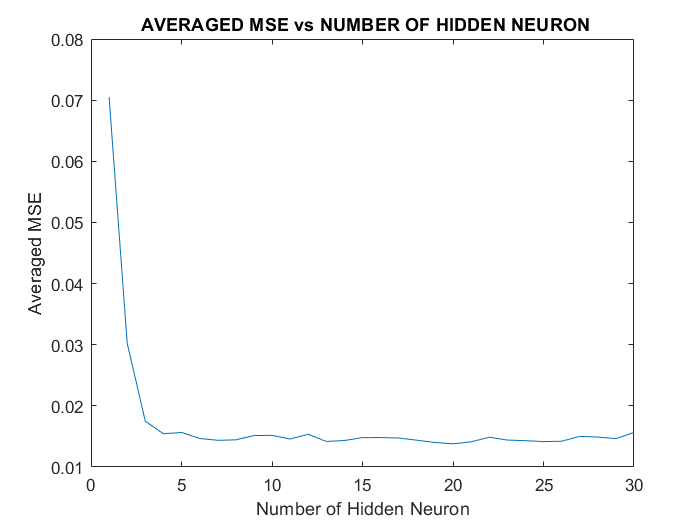

figure;
plot(1:max_num_hidden_neuron,hiddenMatrix)
xlabel('Number of Hidden Neuron')
ylabel('Averaged MSE')
title(' AVERAGED MSE vs NUMBER OF HIDDEN NEURON')

[Maxtask1,Itask1] = max(hiddenMatrix);
fprintf('Worst Performance || Achieved MSE : %.4f Number of Hidden Neuron: %d',Maxtask1,Itask1)

Worst Performance || Achieved MSE : 0.0705 Number of Hidden Neuron: 1

[Mintask1,Itask1] = min(hiddenMatrix);
fprintf('Best Performance || Achieved MSE : %.4f Number of Hidden Neuron: %d',Mintask1,Itask1)

Best Performance || Achieved MSE : 0.0138 Number of Hidden Neuron: 20

Results;

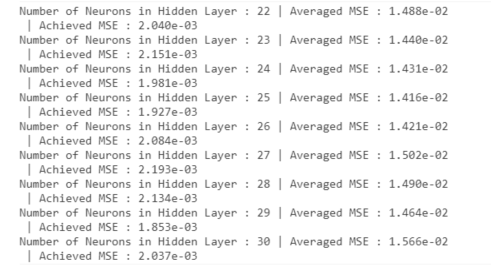

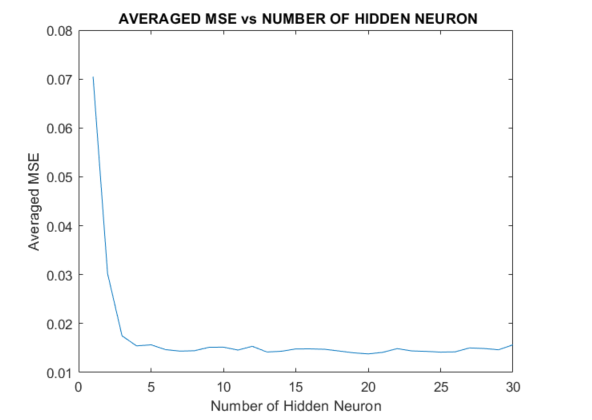

### Task 1(b) 

For a "reasonable" value of accepted MSE tolerance, plot the number of epoch required to achieve such tolerance for different number of neurons in the hidden layer. 

Describe your finding!

*Hint: Why do I put "reasonable" within quotations? You need to do some experimentation to find this reasonable value. Setting too small tolerance may lead your code to run forever, while setting too large tolerance will lead to a non-representative investigation, due to early shutdown because of "lucky" initial guesses. Show and describe the rationale and finding of your experimentations!*

***Answer ;***

In this part, we invastigated the required number of epoch. In task 1a, we observed the mse is changing around 2e-3 (not averaged, achieved). However, for a hidden layer with 1 neuron has the worst mse which is approx 6e-2, so, we set our MSE tolerance to 0.08. However, this tolerance can not give realistic opinion about the required number of epoch. Therefore, we set our MSE tolerance to 0.003 which can give more realistic and applicable results. In addition to these experiements, different learning rate were applied to observe difference in number of epoch. We observed that higher learning rate converge faster than small learning rate and needs less epoch to reach the optimum point. Small learning rate can also cause to not reach the optimum point due to small number of epoch. Beside these, using higher learning rate can cause fluclations at the optimum point. I mean the optimum can be missed by the algorithm, even momentum pull back it , it may not reach the exactly the optimum point.

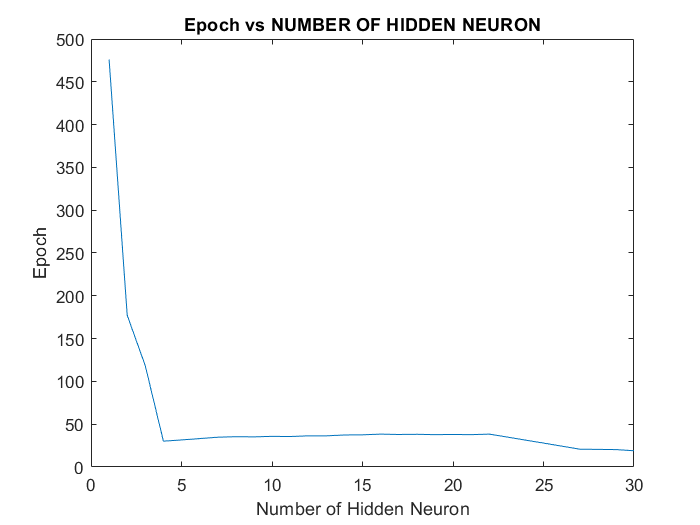

task_limit = 30;
lambda = 1; 
eta = 0.2;        % learning rate   
alpha = 0.8;      % momentum
tol = 0.08;      % error tollerance
max_epoch = 2750;
forced_comment = 'fixed_MSE';
epochMatrix_with_1neuron = zeros(1,task_limit);
for num_hidden_neuron = 1:task_limit
    [Wih_guess,Whj_guess] = guessWeightMatrixs(training_set,desired_test_set,num_hidden_neuron);    
    [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(  training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
                                                
      epochMatrix_with_1neuron(num_hidden_neuron) = task_result ;                                     
end

figure;
plot(1:max_num_hidden_neuron,smooth(epochMatrix_with_1neuron))
xlabel('Number of Hidden Neuron')
ylabel('Epoch')
title ('Epoch vs NUMBER OF HIDDEN NEURON')

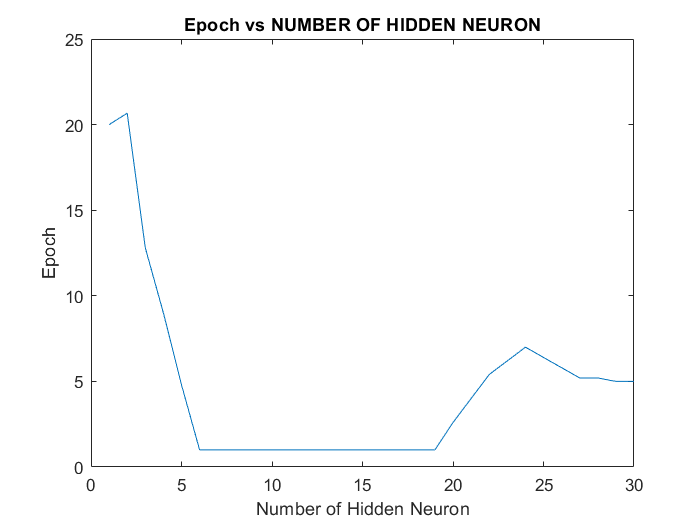

task_limit = 30;
lambda = 1; 
eta = 1.2;        % learning rate   
alpha = 0.8;      % momentum
tol = 0.08;      % error tollerance
max_epoch = 1250;
forced_comment = 'fixed_MSE';
epochMatrix_with_1neuron = zeros(1,task_limit);
for num_hidden_neuron = 1:task_limit
    [Wih_guess,Whj_guess] = guessWeightMatrixs(A,D,num_hidden_neuron);    
    [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(  training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
                                                
      epochMatrix_with_1neuron(num_hidden_neuron) = task_result ;                                     
end

figure;
plot(1:max_num_hidden_neuron,smooth(epochMatrix_with_1neuron))
xlabel('Number of Hidden Neuron')
ylabel('Epoch')
title ('Epoch vs NUMBER OF HIDDEN NEURON')

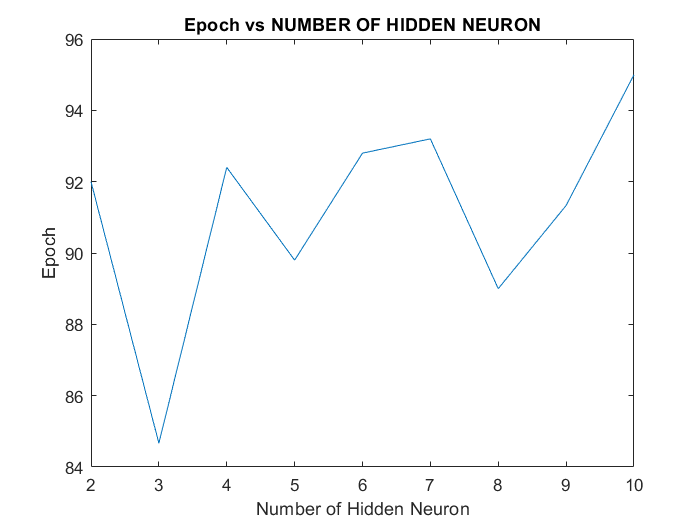

task_limit = 10;
lambda = 1; 
eta = 0.8;        % learning rate   
alpha = 0.5;      % momentum
tol = 0.003;      % error tollerance
max_epoch = 3500;
forced_comment = 'fixed_MSE';
epochMatrix = zeros(1,task_limit-1);
not_using_first_neuron_counter = 1;
for num_hidden_neuron = 2:task_limit
    [Wih_guess,Whj_guess] = guessWeightMatrixs(A,D,num_hidden_neuron);    
    [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(  training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
                                                
      epochMatrix(not_using_first_neuron_counter) = task_result ;
      not_using_first_neuron_counter = not_using_first_neuron_counter + 1;
      
end
figure;
plot(2:not_using_first_neuron_counter,smooth(epochMatrix))
xlabel('Number of Hidden Neuron')
ylabel('Epoch')
title ('Epoch vs NUMBER OF HIDDEN NEURON')

### Results;

Learning Rate = 0.2 , tolerance  = 0.08 ;

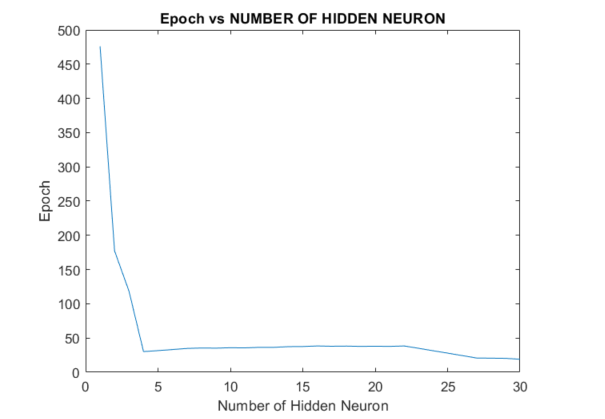

Learning Rate = 1.2 , tolerance  = 0.08 ;

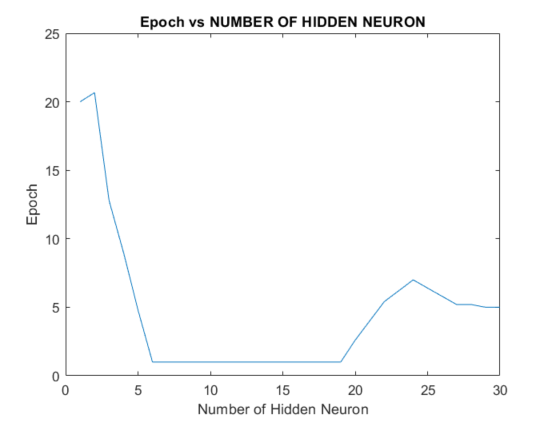

Learning Rate = 0.8 , tolerance  = 0.003 ;

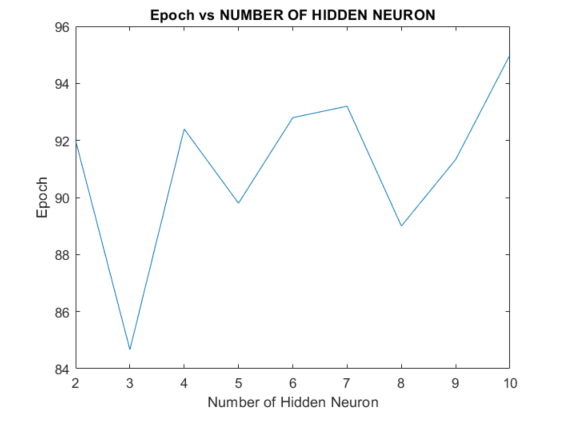

### Task 1(c) 

From task 1(a&b), you should be able to make an "engineering" judgement, regarding what is the reasonable value of MSE tolerance and optimum number of neuron in the hidden layer. Based on those knowledge and your judgement, train an ANN which perform classification of Iris flowers. 

Plot its confusion table and Receiver Operating Characteristic

For a "reasonable" value of accepted MSE tolerance, plot the number of epoch required to achieve such tolerance for different number of neurons in the hidden layer. 

Describe your finding!

*Hint: *`doc plotconfusion`* and *`doc plotroc`

**Answer ; **

From task1a and task2a, we have already idea about required number of hidden neurons and number of epochs. We can say that 5 hidden neurons is breakdown point for MSE, so I think we do not need to use higher than this number of hidden neuron. We also know that, minumum achieved MSE is around 1.8e-3. However, the most of the MSEs for different number of hidden neurons is changing around 2e-3. I prefered to add 1e-3 safety margin to prevent from infite loop (I also added error in the function that gives infinite loop error and ask to change tolerance). Because of these factors, I set my MSE to 3e-3. In addition to this, we can see from task1b that 5 hidden neurons need 91 epochs to achieve this MSE. If I used this number of epoch, probably I could get the desired accuracy due to fact that all random functions use rng(). However, I added safety margin again and I used 150 epochs. 

The other issue is overfitting. In this particular example we have only 4 inputs, and increased epoch and number of hidden neuron will tend to show overfitting on validation data. We can think like a join the dots game we play when we are children. If we use higher epoch and higher number of hidden neuron it will join the always same dots. However, we need to teach our ANN to teach joining the dots. Generalization should be always in case. We need to be careful, when we decide safety margins. 

**Result ; **

**                                               TRANING DATA SET**

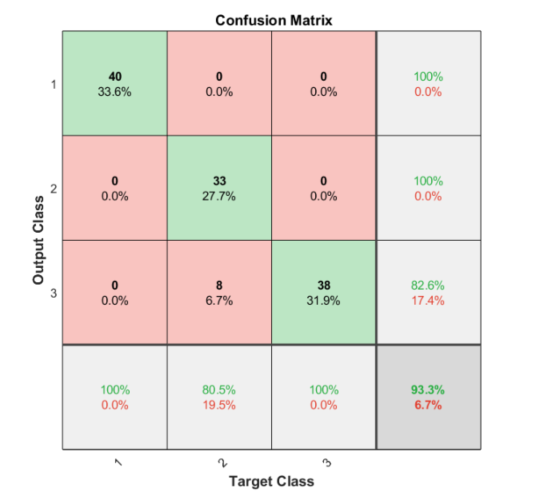

**                                                    TEST DATA SET**

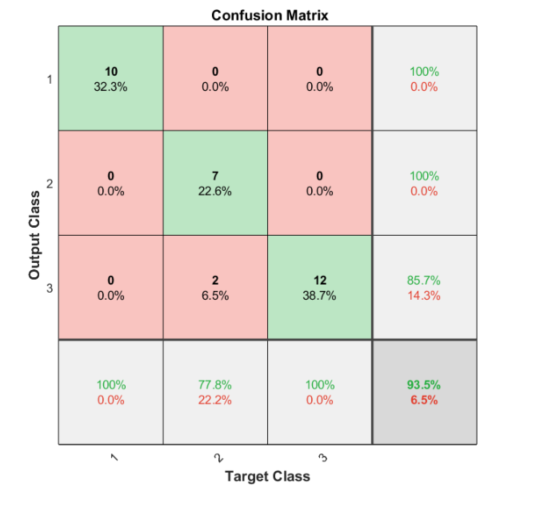

Normally, the proper way to train neural network is using crossvalidation. This allows to avoid from overfitting. The idea is that the data is divided into 3 pieces which are traning, validation and test set. Training continues until there is no improvement in validation set. We can use patternnet function provided by Matlab. Actually, it may have adverse effect on a small data set. 

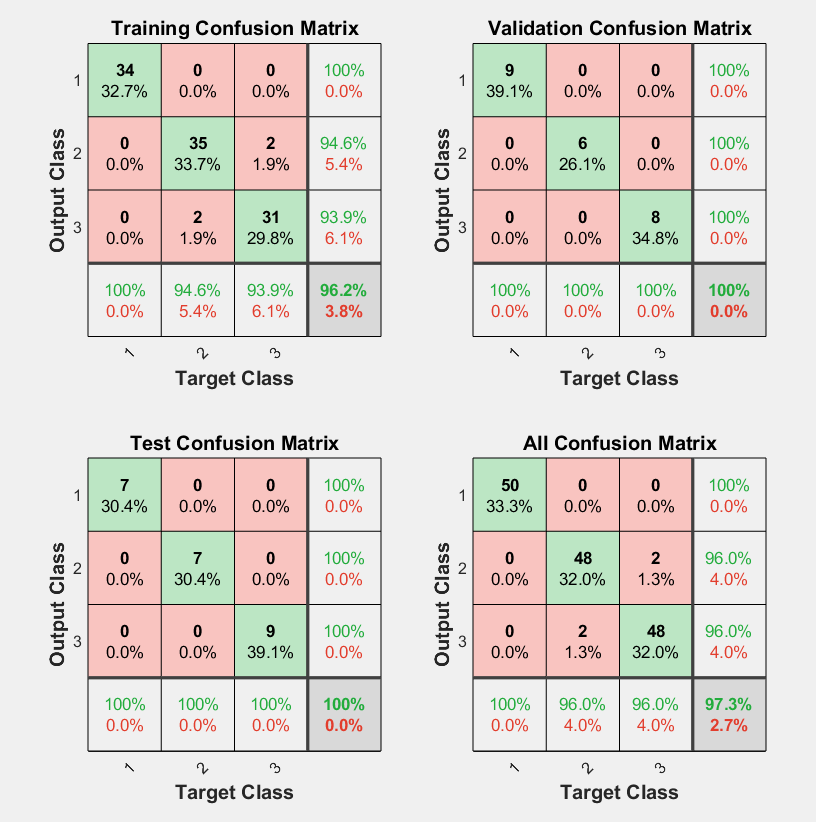

lambda = 1; 
eta = 0.8;        % learning rate   
alpha = 0.5;      % momentum
tol = 0.003;      % error tollerance
num_hidden_neuron = 5;
max_epoch =150;
forced_comment = 'empty'

forced_comment = 'empty'

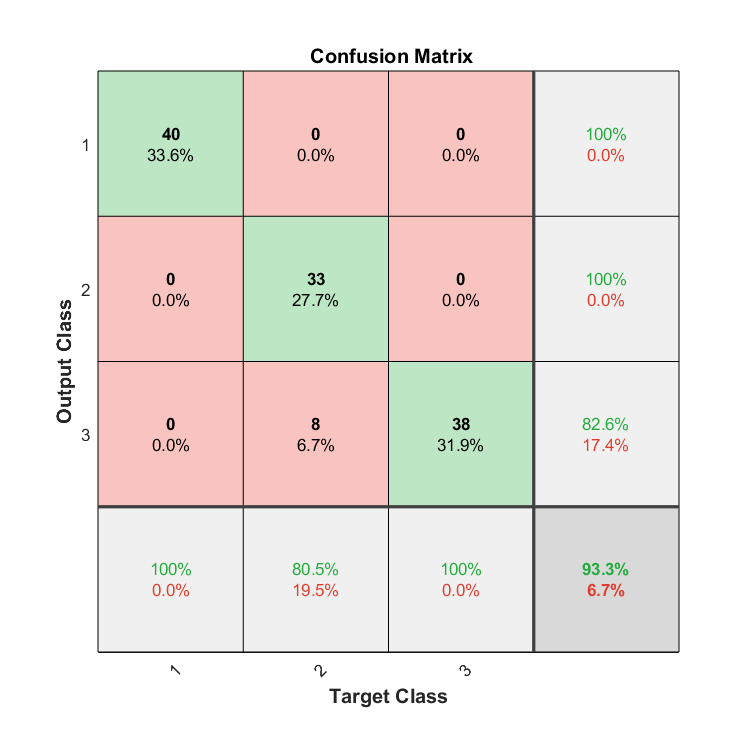

 [Wih_guess,Whj_guess] = guessWeightMatrixs(training_set,desired_test_set,num_hidden_neuron);    
 [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);

%% test for traning set
[~,Nk] = size(training_set);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);training_set]; % hidden layer activation state
        
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)];     % signal of hidden layer for each k 

Yk = transpose(Whj) * psiZk;    % output layer activation state 

psiYk = sigmoid(lambda,Yk);          % signal from output layer

plotconfusion(desired_test_set,psiYk)

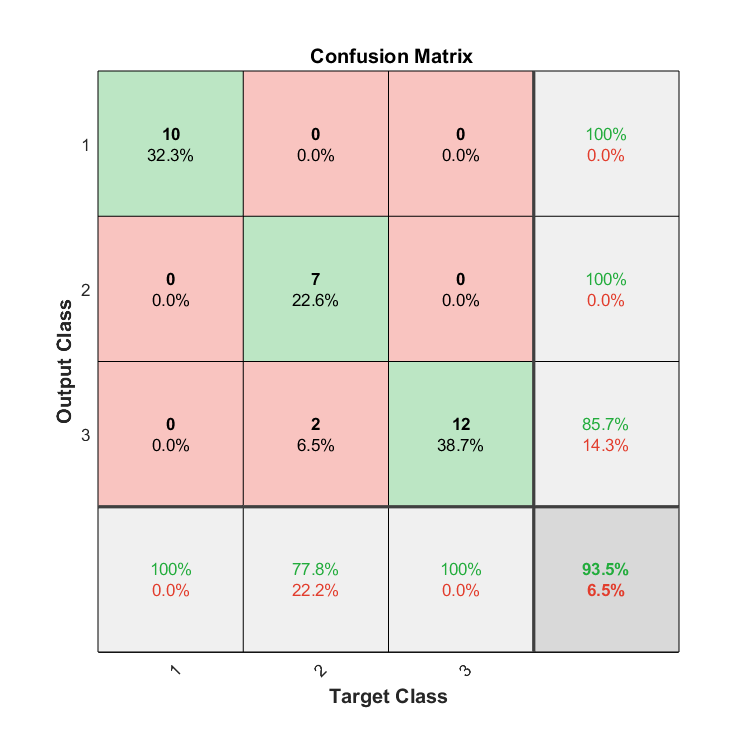

% test for validation set
[~,Nk] = size(validation_set);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);validation_set]; % hidden layer activation state
        
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)];     % signal of hidden layer for each k 

Yk = transpose(Whj) * psiZk;    % output layer activation state 

psiYk = sigmoid(lambda,Yk);     % signal from output layer
                                                      
plotconfusion(desired_validation_set,psiYk)

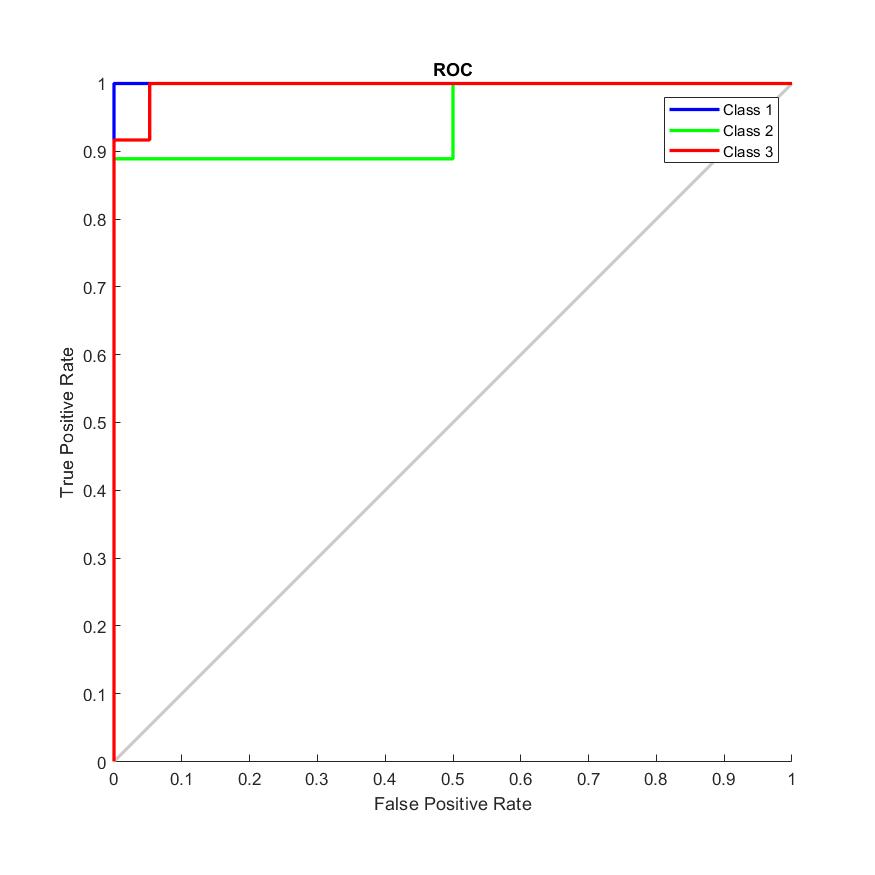

plotroc(desired_validation_set,psiYk)

%{
net = patternnet(5);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainFcn = 'traingd'; %train style
net.trainParam.epochs = 3500;
net.performFcn='sse';
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.008; %learning rate
net.trainParam.mc = 0.005; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,A,D);
view(net)
%}

%{
net = patternnet([15,3]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainFcn = 'traingd'; %train style
net.trainParam.epochs = 3500;
net.performFcn='sse';
net.layers{2}.transferFcn = 'logsig';
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.008; %learning rate
net.trainParam.mc = 0.005; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,A,D);
view(net)
%}

## Question 2 - Artificial Neural Network Application for Hand-Written Roman Number Image Recognition in Black and White [40%]

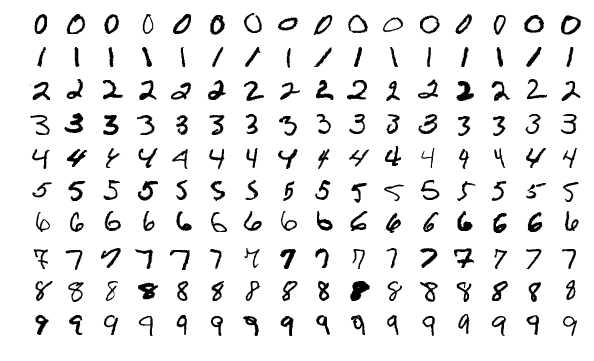

A folder named "handwritten_number_rgb" which contains 301 png files has been included as dataset for Question 2. 

Each png is a 28*28 RGB pixel image.

In addition in this folder, the file index.csv give information of the number written in each file for your convenience. 

**Although the png files given are grey-scalled, for this question image recognition must be done on black and white images.**

You will use, again, the BP blackbox function from Q0 to perform hand-written roman letter recognition. 

Describe your finding!

*Hint: *

*(1) *`doc imread, doc imbinarize`* and *`doc reshape`

`(2)`* assign each pixel to each input neuron*

*(3) how good is the image recognition, which number does single hidden layer ANN able to recognise and which one it doesn't!*

*(4) how do I know how good is my image recognition? Answer: see task 1(c).*

*(5) I will test your code using my image database. My image database simillar to that in "handwritten_number_rgb" folder but I have more images, so do not hardcoded the number of images to 301. *

**PRE-PROCESSING METHOD **

**       Key  Variables**

- mainDirectory, mainDirectory_index  : stores the location of the images and index files respectively. 

- number_of_images_in_file :  Gives number of the images in the file

- image_array : stores images as a bit

- index _file : stores index_file as a table

- desired_output_image_matrix_10bit : stores desired output as a 10 bit

- desired_output_image_matrix_4bit : stored desired output as a  4 bit

        **Key Feautures : These flow charts  give general idea. I also added comments to the codes, it might be helpful to understand as well.**

**                            Reading Images From File and Store Them as a Vector**

           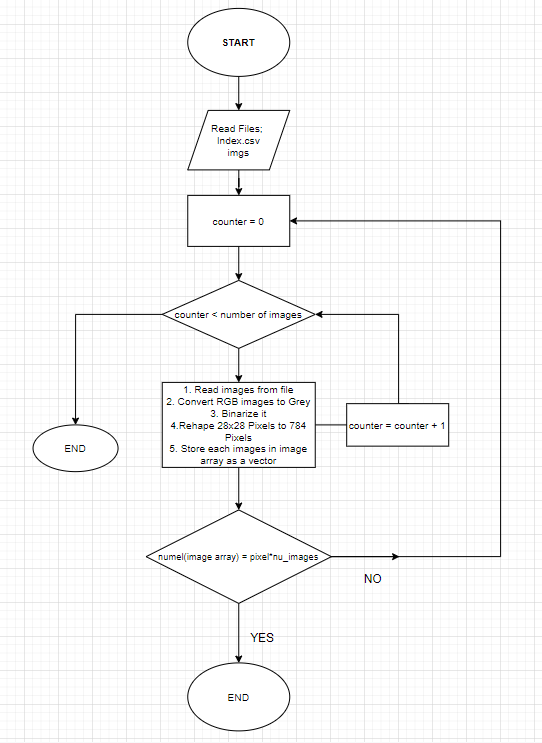

**               Background Change (Corner Pixel Comprasion (1:White, 0:Black))**

             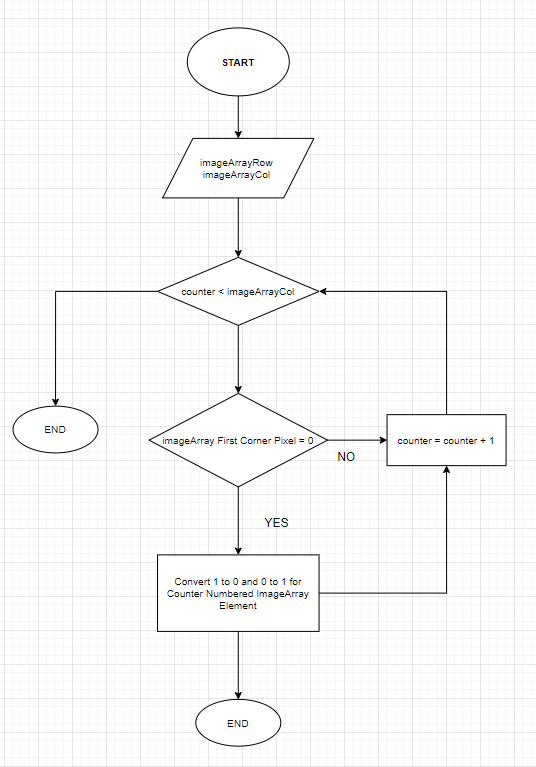

**Note : ** This method is just looking for the corner pixel and a noise in the this pixel might cause to lose noisy data .The more effective method might be drawing triangle starting from corner with limited area  and taking average of the pixels in triangle area. We need to also determine threshold for that process. After averaing and determination of the threshold we can eliminate noise in the corner.

**                                                                                 Output Data **

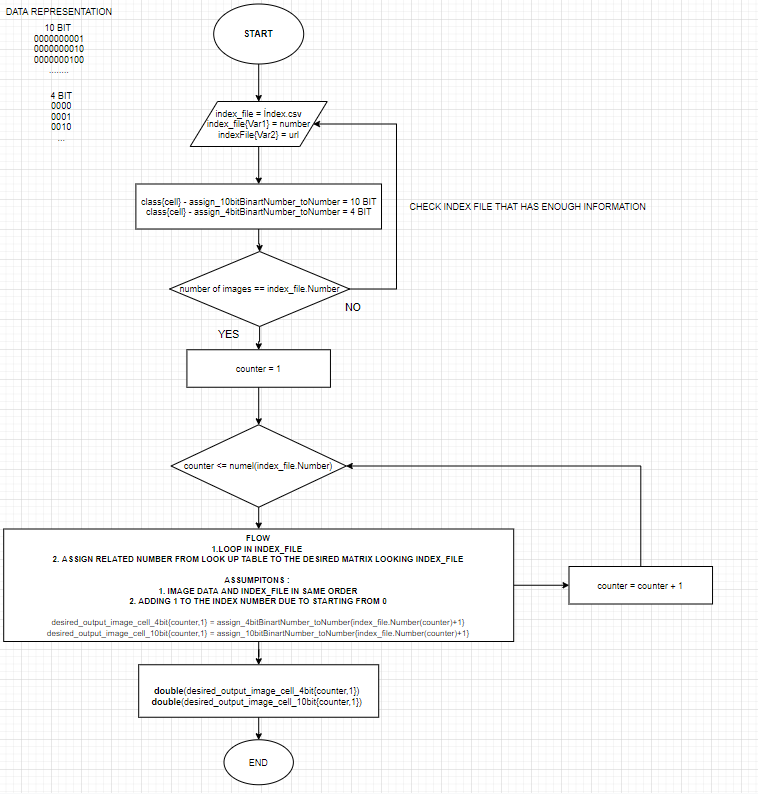

**                                                           DATA VISULATION (CODE IN TASK 3- KINDA PCA)**

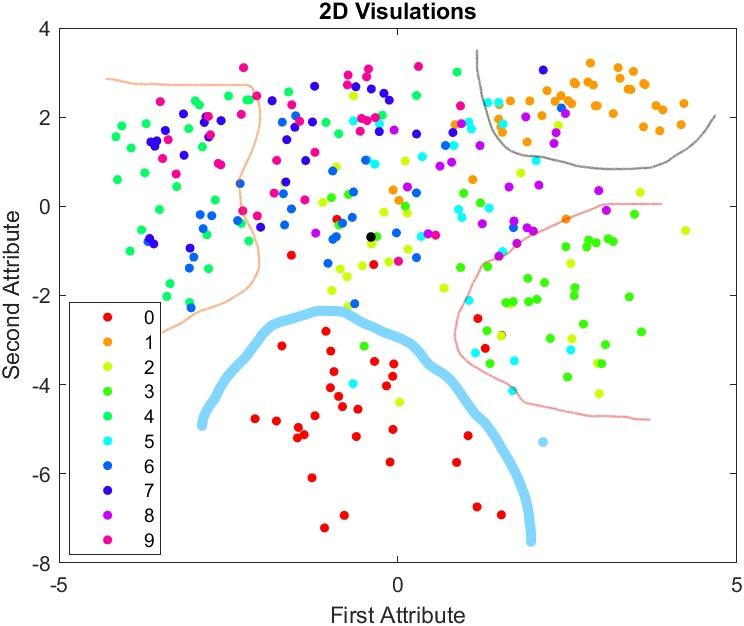

The above figure shows the data in 2D plane, we can say that 0,1,3,4 is more seperatable than other numbers. On the other hand, 6 7 8 9 are much harder to seperate. Now after our experiement we can look for confusion matrix for given data ; 

10 BIT OUTPUT ;

Traning Data,

                             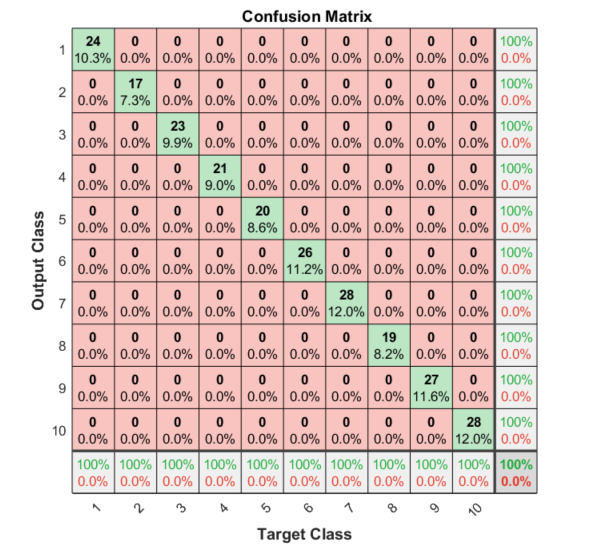

Test Data,

                               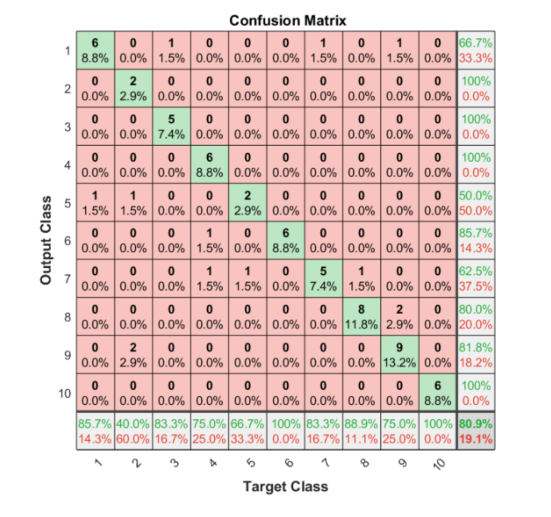

4 BIT OUTPUT ;

Traning Data,

                                   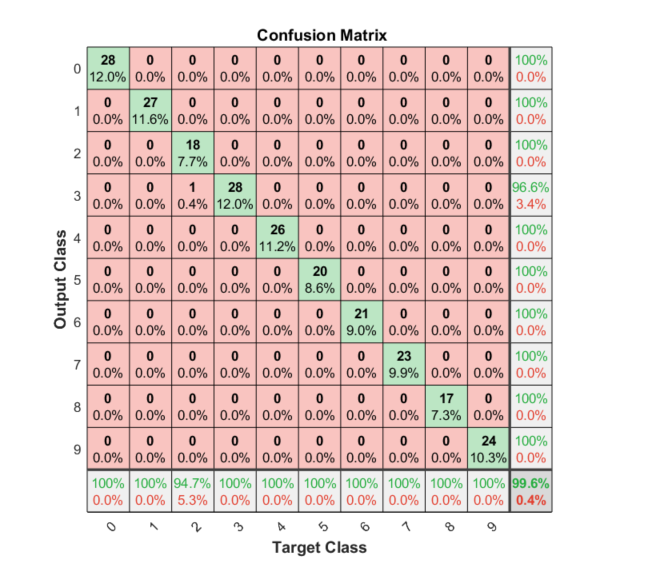

Test Data,

                                         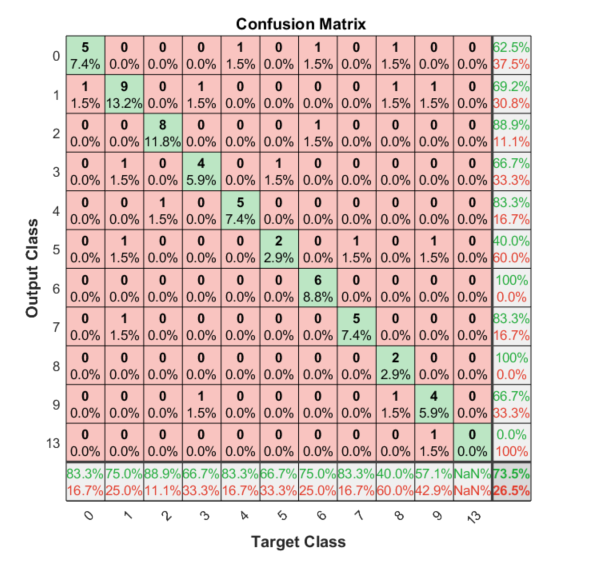

Firstly, I want to describe that the target class order is reversed ( 0 = 10, 1=9, .... 1=9 ).  In our training data, the accuracy is 100% , while the test data accuracy is %81. I think the reason for that, we have only 350 images, and when we divided our data 80% training and %20 test set, the accuracy reduced because data points show different behaviors. For example, some numbers are not aligned in the same position. As we mentioned before, 0 shows the best accuracy, 2 3 and 4 is following the 0. On the other hand, in addition to these numbers 9 also could be separated by the neural network. 5 and 2 are not well separated. The reason can be supported by the 2D visualizations of the whole data set that we can see from that figure, 5 and 2 shows the big range distribution in the plane.

The other factor affected the accuracy is output representation. 10 bit output shows better accuracy than 4 bit output. In addition to this, computing time was enchanced by increased output bit. However, adding extra hidden layer may increase the accuracy for 4 bit output. 

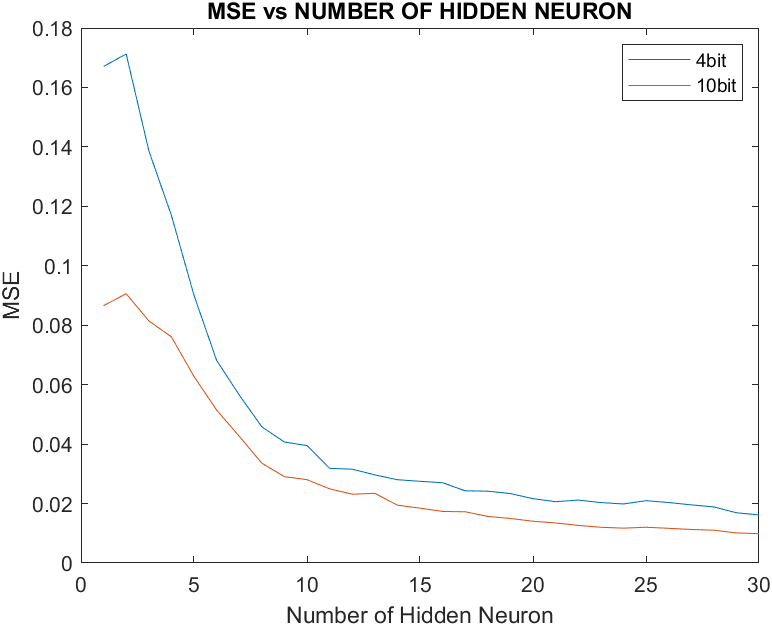

**Note : **For  4 bit output, I used bit represantation and I defined my target classes according to that. Therefore, probably one prediction takes value of  1 1 0 1 and that gives extra target class 13 for 1 data point in validation set. I did not change due to fact that it is wrong so it will not change the accuracy percentage. 

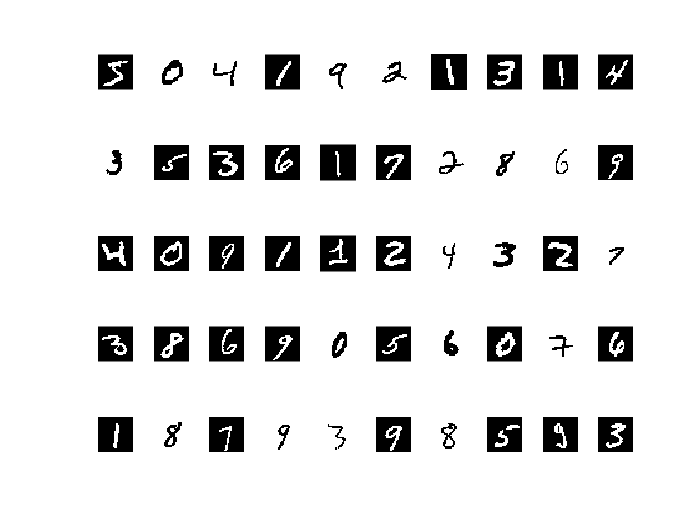

%Preprocessing of the Data

mainDirectory = "C:\Users\ANL\Desktop\imgs"; %Imgs File Position
mainDirectory_index = "C:\Users\ANL\Desktop"; % Index File Position

%Error : Checking image folder is exist
if ~isfolder(mainDirectory)
    error('The Image Folder does not exist') 
end

%Error : Checking index folder is exist
if ~isfolder(mainDirectory_index)
    error('The Index Folder does not exist') 
end


number_of_images_in_file = length(dir(fullfile(mainDirectory,'*.png'))); 

%{
You can use also dir function to assign numbers to Matrix, but the data is
not desireable order. Therefore, you need to use sorting function to sort
the data.
%}


%Opening the image file and assign to matrix
array_counter = 1;
for counter = 0:number_of_images_in_file-1
   temp_string = append('img_',num2str(counter));
   image_url = append(temp_string,'.png');
   file_pattern = fullfile(mainDirectory, image_url);
   image_array(:,array_counter) = reshape(imbinarize(rgb2gray(imread(file_pattern))),[784,1]); % Convert Binary and Vector
   array_counter = array_counter + 1;
end

%Error : Checking images are opened correctly
pixel_number = 784; % 28X28
if (numel(image_array) ~= (pixel_number * number_of_images_in_file))
    error('Images are not opened correctly!!!')
end
figure,
%Checking Manually 
for counter = 1:50
    subplot(5,10,counter);
    imshow(reshape(image_array(:,counter),[28,28]))
end

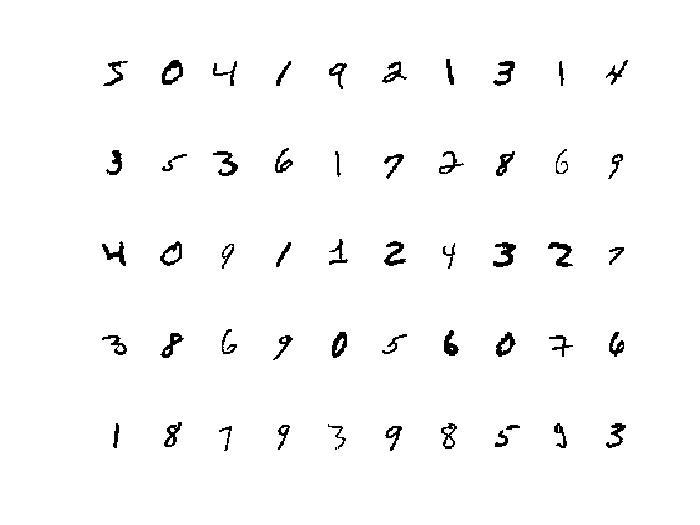


%Making Background same for all (White Background, Black Number, First Pixel Comprasion
[imageArrayRow,imageArrayCol] = size(image_array);
for counter = 1:imageArrayCol
   if image_array(1,counter) == 0
    image_array(:,counter) = ~image_array(:,counter);
   end
end
figure,
% reverse checking (Background is correct or not)
for counter = 1:50
    subplot(5,10,counter);
    imshow(reshape(image_array(:,counter),[28,28]))
end

%Reading index file to get information about Numbers 
index_pattern = fullfile(mainDirectory_index, 'index.csv'); 
index_file = readtable(index_pattern);
index_file.Properties.VariableNames{'Var1'} = 'Number';
index_file.Properties.VariableNames{'Var2'} = 'İmageFileUrl';

%How we reperesent the outputs
%---------------------------------10 Bit--------------------------------
assign_10bitBinartNumber_toNumber = {[0,0,0,0,0,0,0,0,0,1];... % 0
                                    [0,0,0,0,0,0,0,0,1,0];... % 1
                                    [0,0,0,0,0,0,0,1,0,0];... % 2
                                    [0,0,0,0,0,0,1,0,0,0];... % 3
                                    [0,0,0,0,0,1,0,0,0,0];... % 4
                                    [0,0,0,0,1,0,0,0,0,0];... % 5
                                    [0,0,0,1,0,0,0,0,0,0];... % 6
                                    [0,0,1,0,0,0,0,0,0,0];... % 7
                                    [0,1,0,0,0,0,0,0,0,0];... % 8
                                    [1,0,0,0,0,0,0,0,0,0];};  % 9
%-----------------------------------4 Bit--------------------------------

assign_4bitBinartNumber_toNumber = {[0,0,0,0];... % 0
                                    [0,0,0,1];... % 1
                                    [0,0,1,0];... % 2
                                    [0,0,1,1];... % 3
                                    [0,1,0,0];... % 4
                                    [0,1,0,1];... % 5
                                    [0,1,1,0];... % 6
                                    [0,1,1,1];... % 7
                                    [1,0,0,0];... % 8
                                    [1,0,0,1];};  % 9
%------------------------------------------------------------------------                                

image_array = double(image_array); % Convert image_array to double

 %Checking index_file class to allow math operator
 if(class(index_file.Number ~= 'double'))
     index_file.Number = double(index_file.Number); 
 end
 
%Error : Checking index_file has enough information
 if(numel(index_file.Number) ~= number_of_images_in_file)
     error('Index File does not contain enough information'); 
 end
 
% We assign the numbers looking index File for desired output 
desired_output_image_cell_4bit = cell(number_of_images_in_file,1);  
desired_output_image_cell_10bit = cell(number_of_images_in_file,1); 

for counter = 1:numel(index_file.Number)
    desired_output_image_cell_4bit{counter,1} = assign_4bitBinartNumber_toNumber{index_file.Number(counter)+1};
    desired_output_image_cell_10bit{counter,1} = assign_10bitBinartNumber_toNumber{index_file.Number(counter)+1};   
end

%Convert Cell Matrix to Double Matrix
desired_output_image_matrix_10bit = cell2mat(desired_output_image_cell_10bit)'; 
desired_output_image_matrix_4bit = cell2mat(desired_output_image_cell_4bit)';


%*****************************DECISION OF REQUIRED NUMBER OF HIDDEN NEURONS TO ACHIEVE DESIRED MSE***************************
%4 Bits Output
desired_output = desired_output_image_matrix_4bit; % To assign 4 bit output represantation for desired_output

random_style ='fixed_random'; 

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);

lambda = 1; 
eta = 0.07;        % learning rate   
alpha = 0.04;      % momentum
tol = 0.00003;       % MSE error tollerance
max_epoch =350;
forced_comment = 'fixed_epoch'; % Empty will allow run to function without any interupt
task_limit = 30;

for num_hidden_neuron = 1:task_limit

[Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);
[Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
   hiddenMatrix(1,num_hidden_neuron) =task_result ;                                                           
                                                                  
end                                                  

Number of Neurons in Hidden Layer : 1 | Averaged MSE : 1.671e-01 
 | Achieved MSE : 1.563e-01 
Number of Neurons in Hidden Layer : 2 | Averaged MSE : 1.719e-01 
 | Achieved MSE : 1.616e-01 
Number of Neurons in Hidden Layer : 3 | Averaged MSE : 1.748e-01 
 | Achieved MSE : 1.528e-01 
Number of Neurons in Hidden Layer : 4 | Averaged MSE : 9.233e-02 
 | Achieved MSE : 5.285e-02 
Number of Neurons in Hidden Layer : 5 | Averaged MSE : 8.768e-02 
 | Achieved MSE : 6.170e-02 
Number of Neurons in Hidden Layer : 6 | Averaged MSE : 5.817e-02 
 | Achieved MSE : 2.943e-02 
Number of Neurons in Hidden Layer : 7 | Averaged MSE : 3.728e-02 
 | Achieved MSE : 8.387e-03 
Number of Neurons in Hidden Layer : 8 | Averaged MSE : 6.552e-02 
 | Achieved MSE : 3.695e-02 
Number of Neurons in Hidden Layer : 9 | Averaged MSE : 3.407e-02 
 | Achieved MSE : 7.701e-03 
Number of Neurons in Hidden Layer : 10 | Averaged MSE : 3.411e-02 
 | Achieved MSE : 9.064e-03 
Number of Neurons in Hidden Layer : 11 | Averaged

figure;
plot(1:task_limit,smooth(hiddenMatrix))
hold on

%10 Bits Outputs
desired_output = desired_output_image_matrix_10bit;
random_style ='fixed_random'; 

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);

for num_hidden_neuron = 1:task_limit

[Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);
[Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
   hiddenMatrix(1,num_hidden_neuron) =task_result ;                                                           
                                                                  
end             

Number of Neurons in Hidden Layer : 1 | Averaged MSE : 8.658e-02 
 | Achieved MSE : 7.847e-02 
Number of Neurons in Hidden Layer : 2 | Averaged MSE : 9.263e-02 
 | Achieved MSE : 8.990e-02 
Number of Neurons in Hidden Layer : 3 | Averaged MSE : 9.261e-02 
 | Achieved MSE : 8.995e-02 
Number of Neurons in Hidden Layer : 4 | Averaged MSE : 6.949e-02 
 | Achieved MSE : 5.184e-02 
Number of Neurons in Hidden Layer : 5 | Averaged MSE : 6.605e-02 
 | Achieved MSE : 5.631e-02 
Number of Neurons in Hidden Layer : 6 | Averaged MSE : 5.959e-02 
 | Achieved MSE : 4.015e-02 
Number of Neurons in Hidden Layer : 7 | Averaged MSE : 2.606e-02 
 | Achieved MSE : 3.643e-03 
Number of Neurons in Hidden Layer : 8 | Averaged MSE : 3.621e-02 
 | Achieved MSE : 8.284e-03 
Number of Neurons in Hidden Layer : 9 | Averaged MSE : 2.549e-02 
 | Achieved MSE : 3.150e-03 
Number of Neurons in Hidden Layer : 10 | Averaged MSE : 2.059e-02 
 | Achieved MSE : 2.746e-03 
Number of Neurons in Hidden Layer : 11 | Averaged

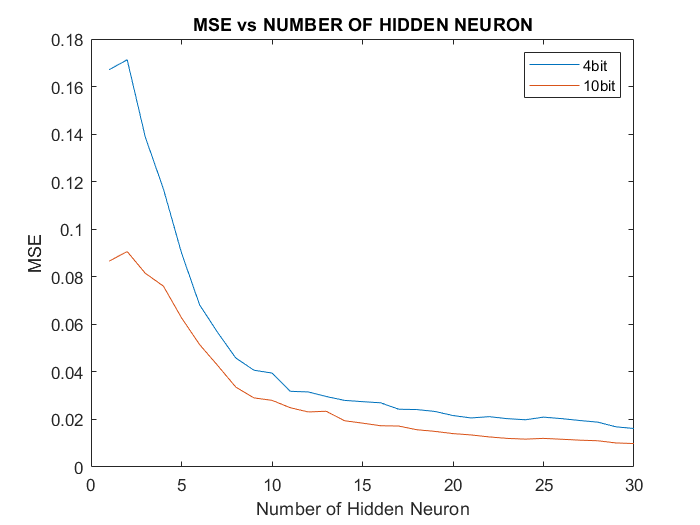

plot(1:task_limit,smooth(hiddenMatrix))
xlabel('Number of Hidden Neuron')
ylabel('MSE')
title ('MSE vs NUMBER OF HIDDEN NEURON') 
legend('4bit','10bit')
hold off

**According the two experiements, achieved MSE is the best at 25 hidden neurons for both conditions. Now we will invastigate the how many epochs we need to get this MSE for 25 hidden neurons for both conditions.**

% *********************************************DECISION OF EPOCHS NUMBER *********************************************
num_hidden_neuron = 25 ; 
max_epoch = 350

max_epoch = 350

tol = 0.003;
forced_comment = 'fixed_MSE';

desired_output = desired_output_image_matrix_4bit;
random_style ='fixed_random'; 

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);

[Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);
[Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);

fprintf('Reuqired Epoch for 4 bits output with 25 hidden neurons | %d',task_result);

Reuqired Epoch for 4 bits output with 25 hidden neurons | 160


desired_output = desired_output_image_matrix_10bit;

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);


[Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);
[Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);

fprintf('Reuqired Epoch for 10 bits output with 25 hidden neurons | %d',task_result);

Reuqired Epoch for 10 bits output with 25 hidden neurons | 101


%************************************************END********************************************************


%**********************************     TEST LEARNING 4 BIT    **************************************************
desired_output = desired_output_image_matrix_4bit; % To assign 4 bit output represantation for desired_output
random_style ='fixed_random';

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);

lambda = 1; 
eta = 0.07;        % learning rate   
alpha = 0.04;      % momentum
tol = 0.003;       % MSE error tollerance
num_hidden_neuron = 25;
max_epoch = 350;
forced_comment = 'empty'; % Empty will allow run to function without any interupt

tic
 [Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);    
 [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
                                                
timeElapsed =toc;
fprintf('Computing Time | %3.e',timeElapsed);

Computing Time | 2e+00

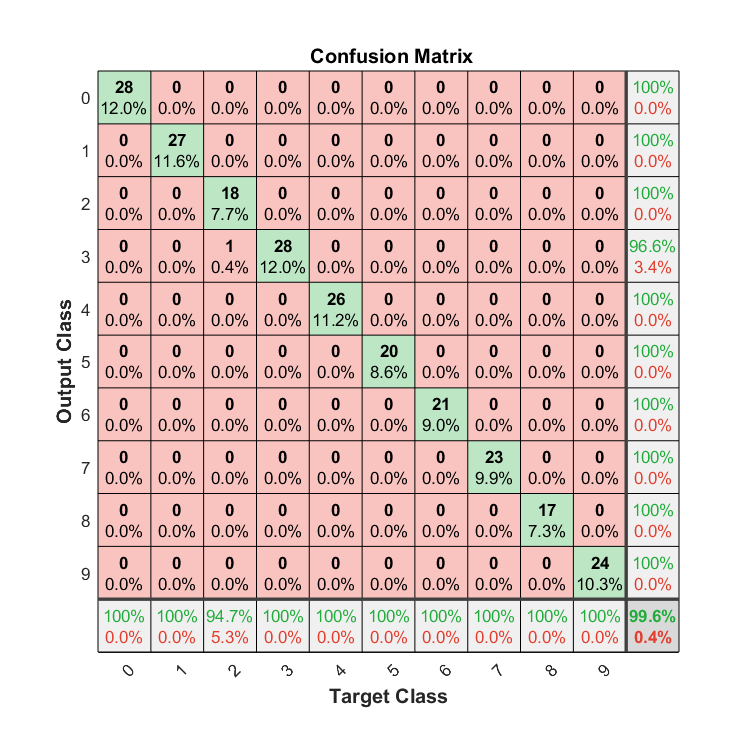


test_result_4_10_bit(Wih,Whj,training_set,desired_test_set,lambda) 

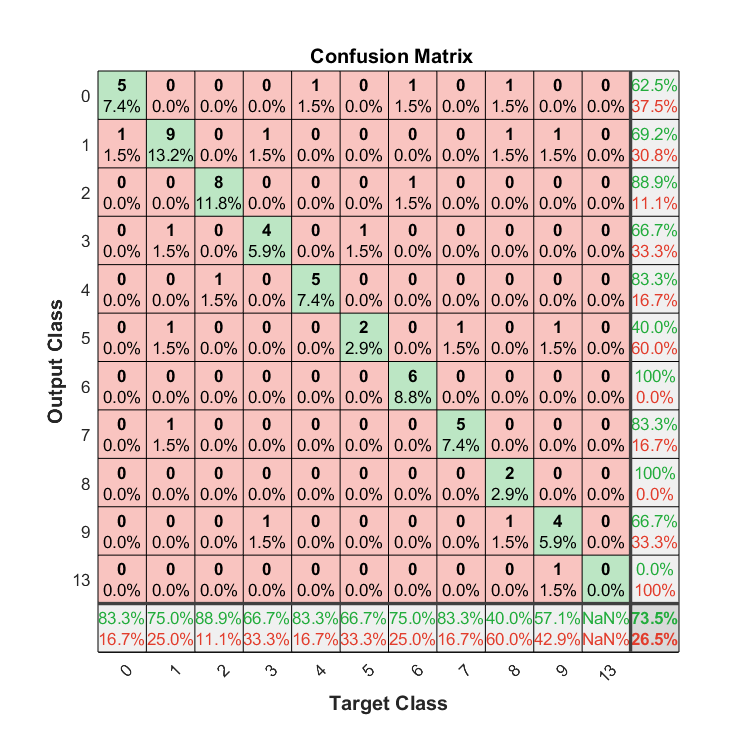

%Validation Test

test_result_4_10_bit(Wih,Whj,validation_set,desired_validation_set,lambda) 


%**********************************     TEST LEARNING 10 BIT    **************************************************


desired_output = desired_output_image_matrix_10bit; % To assign 4 bit output represantation for desired_output
random_style ='fixed_random';

%Data Split Validation and Test
[training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(image_array,desired_output,random_style);

lambda = 1; 
eta = 0.07;        % learning rate   
alpha = 0.04;      % momentum
tol = 0.003;       % MSE error tollerance
num_hidden_neuron = 25;
max_epoch = 350;
forced_comment = 'empty'; % Empty will allow run to function without any interupt

tic
 [Wih_guess,Whj_guess] = guessWeightMatrixsNegative(training_set,desired_test_set,num_hidden_neuron);    
 [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(training_set,...
                                                    desired_test_set,...
                                                    lambda,...
                                                    eta,...
                                                    alpha,...
                                                    tol,...
                                                    num_hidden_neuron,...
                                                    Wih_guess,...
                                                    Whj_guess,...
                                                    forced_comment,...
                                                    max_epoch);
                                                
timeElapsed =toc;
fprintf('Computing Time | %3.e',timeElapsed);

Computing Time | 1e+00

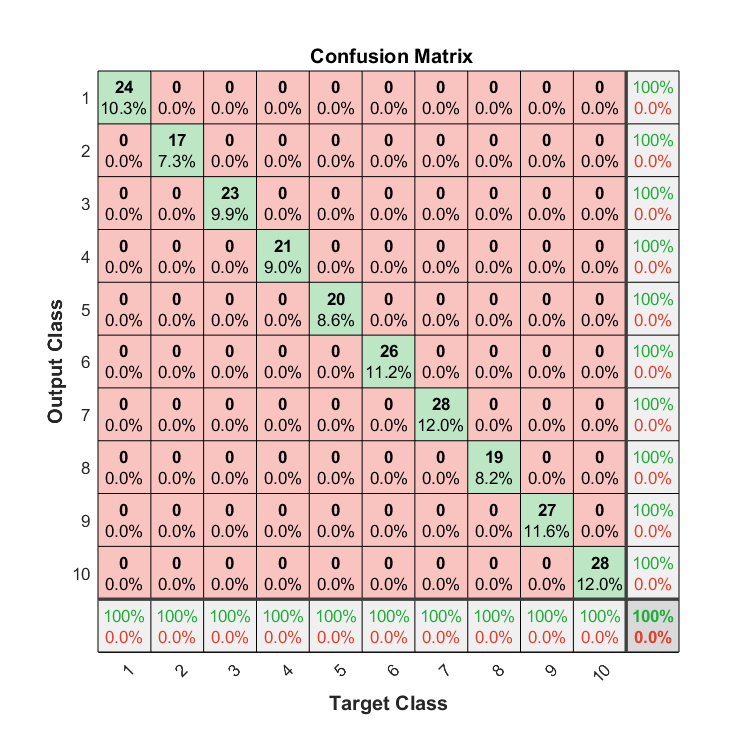


test_result_4_10_bit(Wih,Whj,training_set,desired_test_set,lambda) 

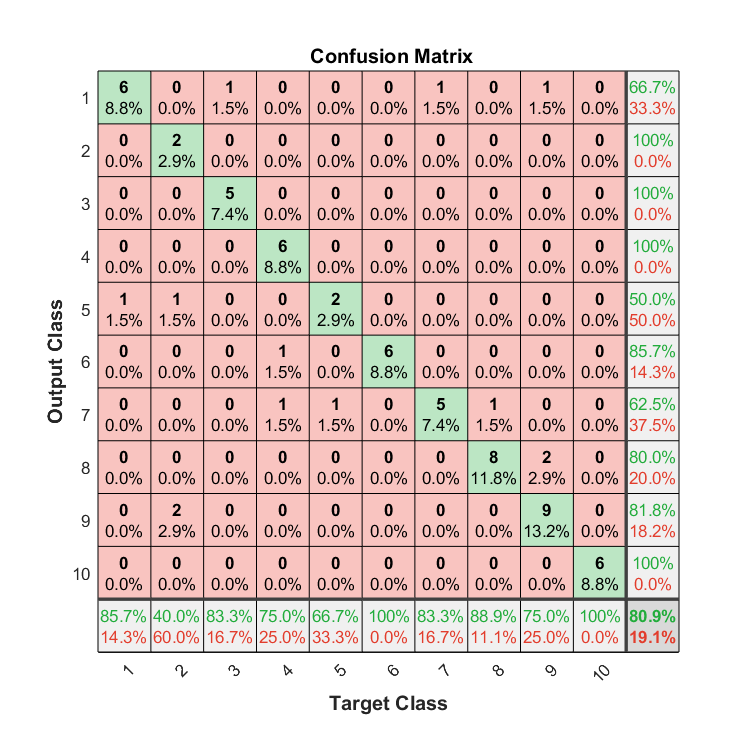

%Validation Test
test_result_4_10_bit(Wih,Whj,validation_set,desired_validation_set,lambda) 

## Question 3 - Artificial Neural Network Application for Hand-Written Roman Number Image Recognition - Optimisation [20%]

For this question, you will use the same dataset as in Question 3. 

In question 2, you have done image recognition for a black-and-white image recognition, with each input neuron is assigned with the value of each pixel using a single hidden layer feedforward ANN. 

*It may be not the optimum way of performing image classification. *

I have designed this question to be open-ended, i.e. there is no right answer. 

For, this question: 

I would like you to think critically how to improve the image classification, that is your classification result here must lead to a better performace compared to that in Question 2.  

You are allowed to perform **any** pre-processing treatment on the training data set, BUT you must justify what is the reason for such treatment.  

Explore, the Matlab feed-forward ANN toolbox which capable to train arbitrary number of hidden layers (see `doc patternnet`). 

*You are encouraged use Matlab implementation of patternet within the Matlab ANN toolbox.* 

Describe your finding!

*Hint: *

*(1) How many number of hidden layers? How many number of neuron in the hidden layer? It is possible to find the optimum value of those? Show and describe the rationale and finding of your experimentations!*

*(2) How do I show that my image recognition here is better than in question 2? *

*(3) I will test your code using my image database. My image database simillar to that in "handwritten_number_rgb" folder but I have more images, so do not hardcoded the number of images to 301. *

 **(1) **Number of hidden layers can determine the accuracy of the neural network. However, 2 hidden layers can be sufficent for most case. I think when we use the higher number of neurons in first layer, we should add second layer with less number of hidden layers. In our example for example, for 4 bit output if we use 100 hidden layers in first hidden layer, using extra hidden with something like 15 might increase the accuracy. Because, the neural network will try to classify 4 output, and using 100 neurons before that will increase the complexity. In other words, I think we need to use extra hidden layers for soft transition. Number of hidden neurons is more determined than the number of hidden layers according to our experiments. 

I think the optimum value of those is not possilbe to find. Because accuracy is function of learning rate, epochs , number of hidden neurons, and how we represent the output. When we change the one of them all structure might change. Therefore, all case should be considered independently. We can find optimum value for spesific learning rate and conditions. Therefore, experiments should be just in the case for spesific configurations. 

The other issue is sample number and diversity of samples. For example, if we had 1500 handwriting images, probably accuracy will be better than our results and our neural network would be more generilazed. 

The other important issue is the activation function used in algorithm. For example, we used logsig function in our experiements due to fact that the output is represented as  0  and 1. I also tried to use hyperbolic tangent function which saturated between [-1 1] . Even I changed the representation of the output. I did not get desired accuracy. 

**OPTIMIZATION ; **

I focused on dimension reduction during my experiements. I used different hidden layers and hidden neurons during my experiements, but I realized that 784 input should be reduced to create much less complex neural network. Therefore I implement convolution ( 3x3 kernel ) to my data set. The other reason for convolution is that I want to maximize difference between the different classes. After this I implemented max pooling due to same reasons. As a last step, I normalized my data due to output representation. The input data reduced to 144 from 784.  The code starts at the line 1005.

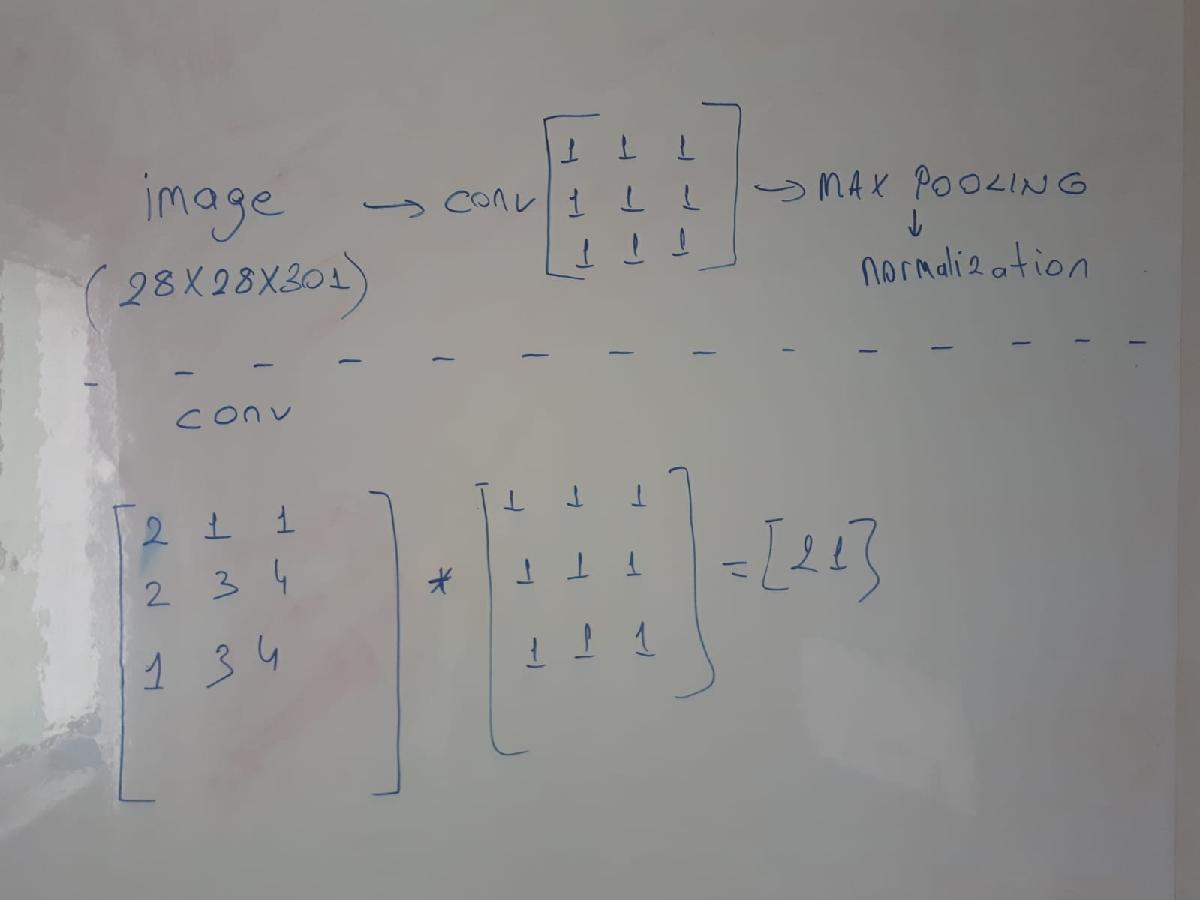

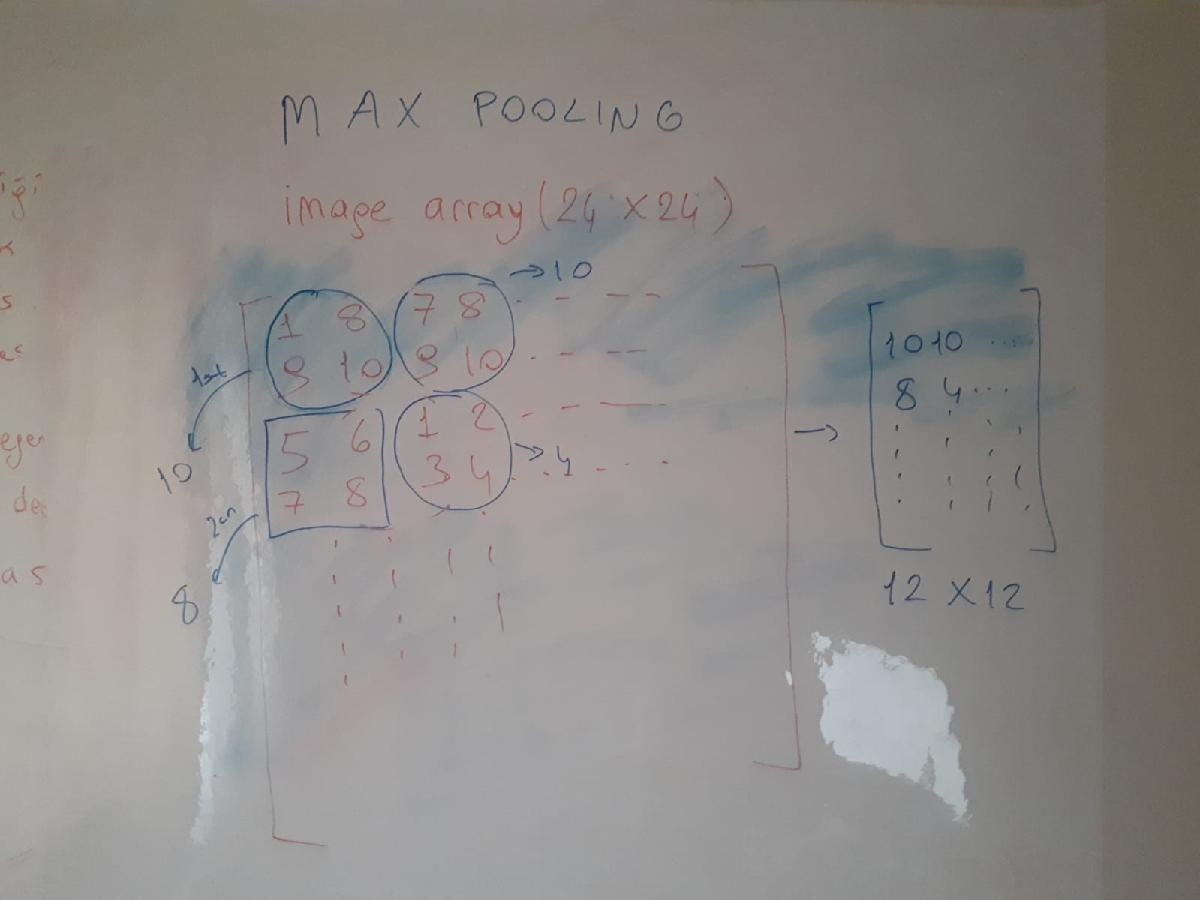

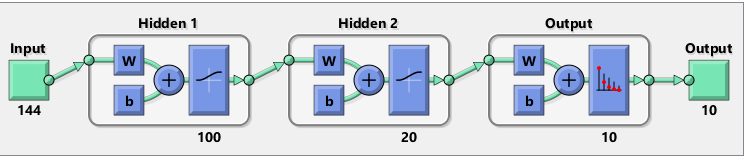

                                  **ACCURACY 91% FOR TEST DATA**

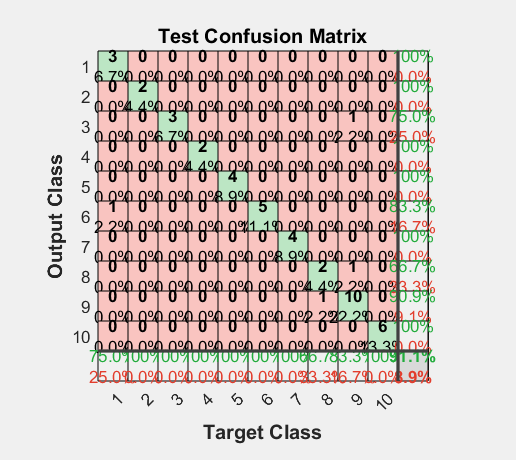

mainDirectory = "C:\Users\ANL\Desktop\imgs"; %Imgs File Position
mainDirectory_index = "C:\Users\ANL\Desktop"; % Index File Position

%Error : Checking image folder is exist
if ~isfolder(mainDirectory)
    error('The Image Folder does not exist') 
end

%Error : Checking index folder is exist
if ~isfolder(mainDirectory_index)
    error('The Index Folder does not exist') 
end

number_of_images_in_file = length(dir(fullfile(mainDirectory,'*.png'))); 

%{
You can use also dir function to assign numbers to Matrix, but the data is
not desireable order. Therefore, you need to use sorting function to sort
the data.
%}

%Opening the image file and assign to matrix
array_counter = 1;
for counter = 0:number_of_images_in_file-1
   temp_string = append('img_',num2str(counter));
   image_url = append(temp_string,'.png');
   file_pattern = fullfile(mainDirectory, image_url);
   image_array(:,array_counter) = reshape(imbinarize(rgb2gray(imread(file_pattern))),[784,1]); % Convert Binary and Vector
   array_counter = array_counter + 1;
end


%Error : Checking images are opened correctly
pixel_number = 784; % 28X28
if (numel(image_array) ~= (pixel_number * number_of_images_in_file))
    error('Images are not opened correctly!!!')
end

%Making Background same for all (White Background, Black Number, First Pixel Comprasion
[imageArrayRow,imageArrayCol] = size(image_array);
for counter = 1:imageArrayCol
   if image_array(1,counter) == 0
    image_array(:,counter) = ~image_array(:,counter);
   end
end

%Reprenstation of Images(White BackGround with Black Number)
figure;

for counter = 1:50
    subplot(5,10,counter);
    imshow(reshape(image_array(:,counter),[28,28]))
end

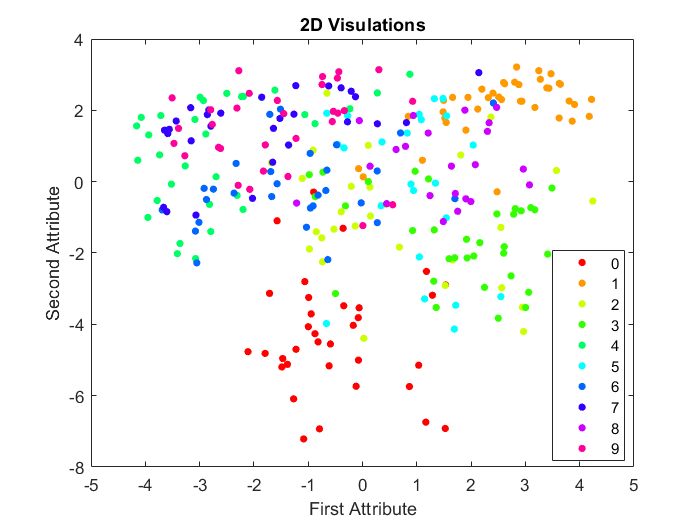

% INDEX FILE FOR DESIRED OUTPUT 

index_pattern = fullfile(mainDirectory_index, 'index.csv'); 
index_file = readtable(index_pattern);

%2D Visulation of Data
conver_matrix = image_array * image_array';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,782),V(:,783)]';
new_cordinates = last_eig_vectors * image_array;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')

%TEST CLASSIFIER LEARNER APP
%{
I tried to discriminate data in 2D using test classifer but performance was
so poor as it is expected.
1.OPEN CLASSIFICATION LEARNER 
2.NEW SESSSION
3.DATA SET VARIABLE = test_classifer_data
4.USE ROW AS A VARIABLE
Self Note: I think these approaches is poor due to binarizaiton. I might be wrong!!!!
%}
test_classifer_data = [new_cordinates;index_file.Var1'];

                                                                        **FINE TREE(X:Misclassifed,O:Correct) (42.2% Accuracy)**

                                                    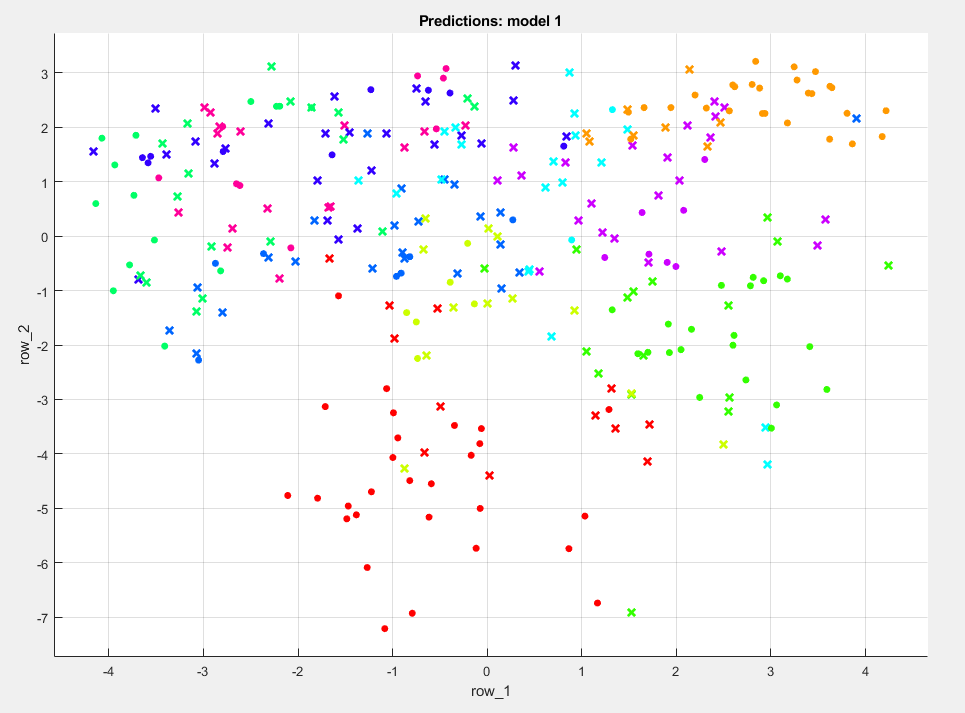

**                                                              COARSE GAUSSIAN SVM(X:Misclassifed,O:Correct) (47.2% Accuracy)**

                                                      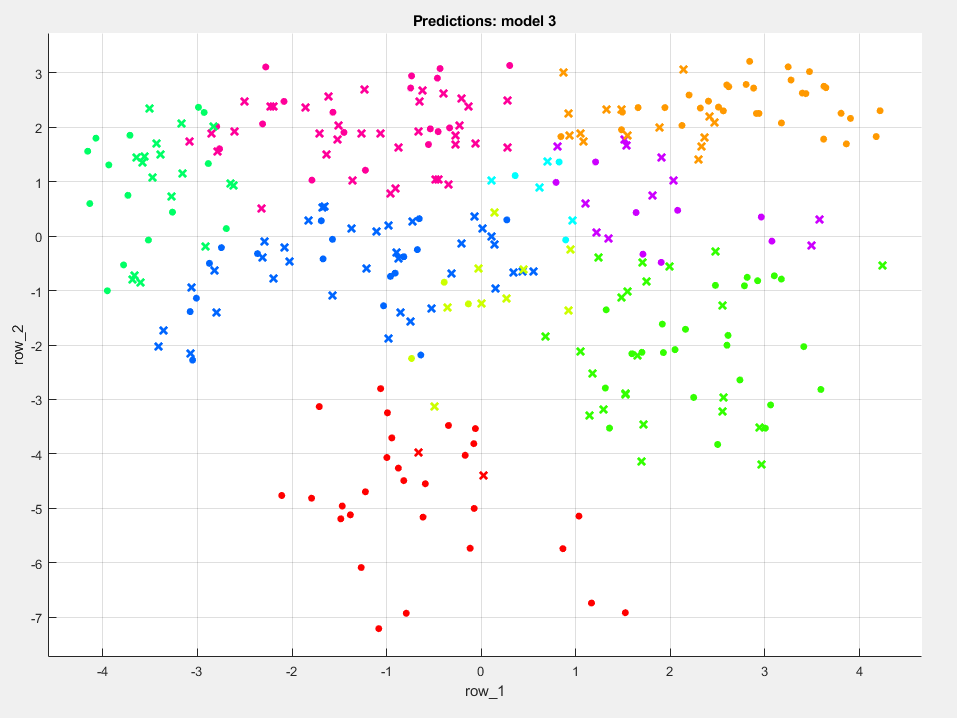

%{
%NOTE : 83% ACCURACY IN TEST DATA  NO SIGNIFICANT IMPROVEMENT (3%), %93 ACCURACY IN VALIDATION
image_array = double(image_array)
[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 4 bit output represantation for desired_output
rng(1);
net = patternnet([100,12]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainParam.min_grad=1e-5;
net.trainFcn = 'traingd'; %back-propagation
net.trainParam.epochs = 350;
net.performFcn='sse';
net.layers{3}.transferFcn = 'softmax';%outputlayer function
net.layers{2}.transferFcn = 'logsig'; %hiddenlayer function
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.005; %learning rate
net.trainParam.mc = 0.003; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,image_array,desired_output);
view(net)
%}



%-------------------------------------------------MAKE A STANDART MODEL----------------------------------

%{
CREATE A ONE MODEL FOR EACH NUMBER

imageArrayRow_cnvl4 = 24

imageArrayCol_cnvl4 = 24

sample_number = 301

NOTE TO MYSELF: MEANINGLESS FOR NEURAL NETWORK, CAN WORK FOR TREES
number_6_idx = (index_file.Var1 == 6)';
number_6_from_image_array = image_array(:,number_6_idx);
for counter = 1:nnz(number_6_idx)
    subplot(5,10,counter);
    imshow(reshape(number_6_from_image_array(:,counter),[28,28]))
end
store_6 = zeros(1,pixel_number);
for row_counter = 1:pixel_number
       store_6(row_counter) = sum(number_6_from_image_array(row_counter,:));
end

for row_counter = 1:pixel_number
    if  store_6(row_counter) < 15
        store_6(row_counter) = 29;
    end
end
 store_6 = store_6'/max(store_6);
 figure,
 imshow(reshape(store_6,[28,28]))
%}
%-------------------------------------------------END------------------------------------------------------


%-------------------------------------------------PLAYING WITH OUTPUT REPRESANTATIONS----------------------------------
%How we reperesent the outputs
%{
%---------------------------------10 Bit--------------------------------
tansig_output=                      {[-1,1,1,1,1,1,1,1,1,1];... % 0
                                    [1,-1,1,1,1,1,1,1,1,1];... % 1

ans =      0     0     0     0     0     0     3     7     7     8     8     3
     0     0     3    10    21    27    36    45    42    40    36    11
     0     0    16    46    64    69    68    66    50    41    34     9
     0     0    17    50    70    72    61    53    28     9     6     1
     0     0     5    21    53    57    27    12     7     0     0     0
     0     0     0     3    28    45    45    33    12     1     0     0
     0     0     0     0     5    28    50    55    45    12     0     0
     0     0     0     0     1     9    32    65    65    25     0     0
     0     0     0     5    23    47    64    69    64    24     0     0
     1     8    21    38    63    68    65    56    33     9     0     0


                                    [1,1,-1,1,1,1,1,1,1,1];... % 2
                                    [1,1,1,-1,1,1,1,1,1,1];... % 3

max_array_row = 12

max_array_col = 12

sample_number = 301

                                    [1,1,1,1,-1,1,1,1,1,1];... % 4
                                    [1,1,1,1,1,-1,1,1,1,1];... % 5
                                    [1,1,1,1,1,1,-1,1,1,1];... % 6
                                    [1,1,1,1,1,1,1,-1,1,1];... % 7
                                    [1,1,1,1,1,1,1,1,-1,1];... % 8
                                    [1,1,1,1,1,1,1,1,1,-1];};  % 9

ans =          0         0         0         0         0         0    0.0417    0.0972    0.0972    0.1111    0.1111    0.0417
         0         0    0.0417    0.1389    0.2917    0.3750    0.5000    0.6250    0.5833    0.5556    0.5000    0.1528
         0         0    0.2222    0.6389    0.8889    0.9583    0.9444    0.9167    0.6944    0.5694    0.4722    0.1250
         0         0    0.2361    0.6944    0.9722    1.0000    0.8472    0.7361    0.3889    0.1250    0.0833    0.0139
         0         0    0.0694    0.2917    0.7361    0.7917    0.3750    0.1667    0.0972         0         0         0
         0         0         0    0.0417    0.3889    0.6250    0.6250    0.4583    0.1667    0.0139         0         0
         0         0         0         0    0.0694    0.3889    0.6944    0.7639    0.6250    0.1667         0         0
         0         0         0         0    0.0139    0.1250    0.4444    0.9028    0.9028    0.3472         0         0
         0         0      



for counter = 1:numel(index_file.Var1)
    desired_output_image_cell_10bit{counter,1} = tansig_output{index_file.Var1(counter)+1};   
end

%Convert Cell Matrix to Double Matrix
desired_output_image_matrix_10bit = cell2mat(desired_output_image_cell_10bit)'; 
%}
%-------------------------------------------------END--------------------------------------------------------------------

%{
%-------------------------------------------------PLAYING WITH INPUT REPRESANTATIONS----------------------------------
[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output

image_array_rchange = zeros(imageArrayRow,imageArrayCol);
for col_counter = 1:imageArrayCol
    for row_counter = 1:imageArrayRow
        if image_array(row_counter,col_counter) == 0
            image_array_rchange(row_counter,col_counter) = -1;
        else
            image_array_rchange(row_counter,col_counter) = image_array(row_counter,col_counter);
        end
    end
end
rng(1)
image_array_rchange = image_array_rchange * 0.5;
net = patternnet(25);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 16;
net.trainParam.min_grad=0;
net.trainFcn = 'traingd'; %back-propagation
net.trainParam.epochs = 3000;
net.performFcn='sse';
net.layers{2}.transferFcn = 'softmax'; %outputlayer function
net.layers{1}.transferFcn = 'tansig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.005; %learning rate
net.trainParam.mc = 0.003; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,image_array_rchange,desired_output);
view(net)
%-------------------------------------------------END----------------------------------------------------------------
%}


%-------------------------------------------------DETECTION OF NUMBER OF HIDDEN NEURON----------------------------------

%{
[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output

inputs = image_array;
targets = desired_output;

for num_hidden_neuron = 1:30
net = patternnet(num_hidden_neuron);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainParam.min_grad=1e-5;
net.trainFcn = 'traingd'; %back-propagation
net.trainParam.epochs = 3000;
net.performFcn='sse';
net.layers{2}.transferFcn = 'softmax'; %outputlayer function
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.005; %learning rate
net.trainParam.mc = 0.003; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,inputs,targets);
outputs=net(inputs);
[values,pred_ind]=max(outputs,[],1);
[~,actual_ind]=max(targets,[],1);
accuracy=sum(pred_ind==actual_ind)/size(inputs,2)*100

end
%}

%-------------------------------------------------END----------------------------------------------------------

%-------------------------------------------------KERNEL FILTERS----------------------------------------------------------
%{
kernel_filter_1 = [0, -0.5 ,0 ; -0.5 3 -0.5; 0 -0.5 0] %SHARPENING
kernel_filter_2 = [1/9,1/9,1/9; 1/9,1/9,1/9;1/9,1/9,1/9] %BLUR
for col_counter = 1:imageArrayCol
    
     first_filter = conv2(reshape(image_array(:,col_counter),[28,28]),kernel_filter_2);
     filtered_image_array(:,col_counter) = reshape(first_filter,[900,1]);
end


for counter = 1:50
    subplot(5,10,counter);
    imshow(reshape(filtered_image_array(:,counter),[30,30]))
end
%2D Visulation of Data
conver_matrix = filtered_image_array * filtered_image_array';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,898),V(:,899)]';
new_cordinates = last_eig_vectors * filtered_image_array;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')

[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output
rng(1);
net = patternnet([100,12]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainParam.min_grad=1e-5;
net.trainFcn = 'traingd'; %back-propagation
net.trainParam.epochs = 350;
net.performFcn='sse';
net.layers{3}.transferFcn = 'softmax';%outputlayer function
net.layers{2}.transferFcn = 'logsig'; %hiddenlayer function
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.005; %learning rate
net.trainParam.mc = 0.003; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,filtered_image_array,desired_output);
view(net)


%}

%-------------------------------------------------END----------------------------------------------------------

%{
%-------------------------------------------------DIMENSION REDUCTION----------------------------------------------------------
image_array_rchange = zeros(imageArrayRow,imageArrayCol);
for col_counter = 1:imageArrayCol
    for row_counter = 1:imageArrayRow
        if image_array(row_counter,col_counter) == 1
            image_array_rchange(row_counter,col_counter) = 0;
        else
            image_array_rchange(row_counter,col_counter) = 1;
        end
    end
end


[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output

for counter = 1:number_of_images_in_file
imds(:,:,counter) = reshape(image_array_rchange(:,counter),[28,28]);
end

kernel_filter_3X3 = 1/9 * [1, 1 ,1 ; 1, 1, 1; 1, 1, 1];

%Average Pooling
for counter = 1:number_of_images_in_file
 convresult_layer1(:,:,counter) = conv2(imds(:,:,counter),kernel_filter_3X3,'valid');
 convresult_layer2(:,:,counter) = conv2(convresult_layer1(:,:,counter),kernel_filter_3X3,'valid');
end

for counter = 1:number_of_images_in_file
filtered_image_array(:,counter) = reshape(convresult_layer2(:,:,counter),[576,1]);
end


%2D Visulation of Data
conver_matrix = filtered_image_array * filtered_image_array';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,574),V(:,575)]';
new_cordinates = last_eig_vectors * filtered_image_array;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')
kernel_filter_3X3 = ones(3,3)
for counter = 1:number_of_images_in_file
 convresult_layer3(:,:,counter) = conv2(convresult_layer2(:,:,counter),kernel_filter_3X3,'valid');
end 

for counter = 1:number_of_images_in_file
filtered_image_array_storage(:,counter) = reshape(convresult_layer3(:,:,counter),[484,1]);
end

%2D Visulation of Data
conver_matrix = filtered_image_array_storage * filtered_image_array_storage';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,482),V(:,483)]';
new_cordinates = last_eig_vectors * filtered_image_array_storage;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')
%{
[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output
rng(1);
net = patternnet([100,12]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainParam.min_grad=1e-5;
net.trainFcn = 'traingd'; %back-propagation
net.trainParam.epochs = 350;
net.performFcn='sse';
net.layers{3}.transferFcn = 'softmax';%outputlayer function
net.layers{2}.transferFcn = 'logsig'; %hiddenlayer function
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.005; %learning rate
net.trainParam.mc = 0.003; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,filtered_image_array_storage,desired_output);
view(net)
%}


kernel_filter_3X3 = [1, 1 ,1 ; 1, 1, 1; 1, 1, 1];


for counter = 1:number_of_images_in_file
 convresult_layer4(:,:,counter) = conv2(convresult_layer3(:,:,counter),kernel_filter_3X3,'valid');
end 

for counter = 1:number_of_images_in_file
filtered_image_array_storage_2(:,counter) = reshape(convresult_layer4(:,:,counter),[400,1]);
end

%2D Visulation of Data
conver_matrix = filtered_image_array_storage_2 * filtered_image_array_storage_2';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,398),V(:,399)]';
new_cordinates = last_eig_vectors * filtered_image_array_storage_2;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')
[imageArrayRow_cnvl4,imageArrayCol_cnvl4,sample_number] = size(convresult_layer4)

pixel_1 = 0;
pixel_2 = 0;
pixel_3 = 0;
pixel_4 = 0;

max_pixel_array = ones(10,10,sample_number);
inner_row_counter = 1;
inner_col_counter = 1;
for sample_counter = 1:sample_number
    for col_counter = 1:2:imageArrayCol_cnvl4-1
       for row_counter = 1:2:imageArrayRow_cnvl4-1
             pixel_1 = convresult_layer4(row_counter,col_counter,sample_counter);
             pixel_2 = convresult_layer4(row_counter,col_counter+1,sample_counter);
             pixel_3 = convresult_layer4(row_counter+1,col_counter,sample_counter);
             pixel_4 = convresult_layer4(row_counter+1,col_counter+1,sample_counter);
             
             temp_pixel_matrix = [pixel_1,pixel_2,pixel_3,pixel_4];
             max_pixel = max(temp_pixel_matrix);
             max_pixel_array(inner_row_counter,inner_col_counter,sample_counter) = max_pixel;
             inner_row_counter = inner_row_counter + 1;
       end
       inner_col_counter = inner_col_counter + 1;
       inner_row_counter = 1;
    end
    inner_col_counter = 1;
end

for counter = 1:number_of_images_in_file
filtered_image_array_storage_3(:,counter) = reshape(max_pixel_array(:,:,counter),[100,1]);
end

%2D Visulation of Data
conver_matrix = filtered_image_array_storage_3 * filtered_image_array_storage_3';
[V,D] = eig(conver_matrix);
last_eig_vectors = [V(:,98),V(:,99)]';
new_cordinates = last_eig_vectors * filtered_image_array_storage_3;
figure,
gscatter(new_cordinates(1,:),new_cordinates(2,:),index_file.Var1)
xlabel('First Attribute')
ylabel('Second Attribute')
title('2D Visulations')

[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output
rng(1);
net = patternnet([100,12]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainParam.min_grad=1e-5;
net.trainFcn = 'traingd'; %train style
net.trainParam.epochs = 3500;
net.performFcn='sse';
net.layers{3}.transferFcn = 'softmax';%outputlayer function
net.layers{2}.transferFcn = 'logsig'; %hiddenlayer function
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.0045; %learning rate
net.trainParam.mc = 0.0030; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,filtered_image_array_storage_3,desired_output);
view(net)

%}

%-------------------------------------------------END----------------------------------------------------------


%Convolution Layers 
kernel_filter_3X3 = [1, 1 ,1 ; 1, 1, 1; 1, 1, 1];

image_array_rchange = zeros(imageArrayRow,imageArrayCol);
for col_counter = 1:imageArrayCol
    for row_counter = 1:imageArrayRow
        if image_array(row_counter,col_counter) == 1
            image_array_rchange(row_counter,col_counter) = 0;
        else
            image_array_rchange(row_counter,col_counter) = 1;
        end
    end
end

for counter = 1:number_of_images_in_file
imds(:,:,counter) = reshape(image_array_rchange(:,counter),[28,28]);
end

for counter = 1:number_of_images_in_file
 convresult_layer1(:,:,counter) = conv2(imds(:,:,counter),kernel_filter_3X3,'valid');
end 

for counter = 1:number_of_images_in_file
 convresult_layer2(:,:,counter) = conv2(convresult_layer1(:,:,counter),kernel_filter_3X3,'valid');
end 






[imageArrayRow_cnvl4,imageArrayCol_cnvl4,sample_number] = size(convresult_layer2)
% MAX POOLING ALGORITHM
pixel_1 = 0;
pixel_2 = 0;
pixel_3 = 0;
pixel_4 = 0;

max_pixel_array = ones(12,12,sample_number);
inner_row_counter = 1;
inner_col_counter = 1;
for sample_counter = 1:sample_number
    for col_counter = 1:2:imageArrayCol_cnvl4-1
       for row_counter = 1:2:imageArrayRow_cnvl4-1
             pixel_1 = convresult_layer2(row_counter,col_counter,sample_counter);
             pixel_2 = convresult_layer2(row_counter,col_counter+1,sample_counter);
             pixel_3 = convresult_layer2(row_counter+1,col_counter,sample_counter);
             pixel_4 = convresult_layer2(row_counter+1,col_counter+1,sample_counter);
             
             temp_pixel_matrix = [pixel_1,pixel_2,pixel_3,pixel_4];
             max_pixel = max(temp_pixel_matrix);
             max_pixel_array(inner_row_counter,inner_col_counter,sample_counter) = max_pixel;
             inner_row_counter = inner_row_counter + 1;
       end
       inner_col_counter = inner_col_counter + 1;
       inner_row_counter = 1;
    end
    inner_col_counter = 1;
end

% Normalization of data
max_pixel_array(:,:,1)

[max_array_row,max_array_col,sample_number] = size(max_pixel_array)
max_pixel_array_normalized = zeros(max_array_row,max_array_col,sample_number);
for counter = 1:sample_number
    max_pixel_array_normalized(:,:,counter) = max_pixel_array(:,:,counter)/max(max(max_pixel_array(:,:,counter)));
    
end
max_pixel_array_normalized(:,:,1)
for counter = 1:number_of_images_in_file
filtered_image_array_storage(:,counter) = reshape(max_pixel_array_normalized(:,:,counter),[max_array_row*max_array_col,1]);
end

%NEURAL NETWORK CONFIGURATION

[desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file);
desired_output = desired_output_image_matrix_10bit; % To assign 10 bit output represantation for desired_output
rng(1);
net = patternnet([100,20]);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
net.trainParam.max_fail = 6;
net.trainFcn = 'traingd'; %train style
net.trainParam.epochs = 10000;
net.performFcn='sse';
net.layers{2}.transferFcn = 'logsig';
net.layers{1}.transferFcn = 'logsig'; %hiddenlayer function
net.trainParam.goal = 0; 
net.trainParam.lr = 0.002; %learning rate
net.trainParam.mc = 0.001; %momentum
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};
net = train(net,filtered_image_array_storage,desired_output);
view(net)
















## WRITE YOUR LOCAL FUNCTIONS BELOW:


%{ 

FUNCTION LIST

1-) dataSplit : Split the data traning and validation set ( can be used as
a test set). Attributes ; shufle and fixed_random. Shufle gives different
numbers everytime, while fixed_random uses rng function to give same
numbers.

2-) normalizationofMatrix : Normalize the Matrix

3-) guessWeightMatrixs : Initilaze the guess matrixes

4-) guessWeightMatrixsNegative : Initilze the guess matrixes (including
negative numbers)

5-) backpropagatio_1hiddenlayer_blackbox : back-propagation core algorithm

6-) testresult_4_10_bit :  gives the accuracy of the prediction

7-)desiredoutput : gives 4bit and 10 bit represetantion of the output using
index_file where the numbers are storaged.


%}



%********************************* DATA SPLIT, VALIDATION AND TEST SET *********************************

function [training_set,validation_set,desired_test_set,desired_validation_set] = dataSplit(A,D,string)

[n,p] = size(A); 

if (strcmp(string,'shufle'))
    rng('shuffle'); % To avoid from getting same data point every timme
    temp = rand(1,p);
    training_set = A(:,temp<0.8); %Approx 80% of data set
    validation_set = A(:,~(temp<0.8)); %Approx 20% of data set
    desired_test_set = D(:,temp<0.8);
    desired_validation_set = D(:,~(temp<0.8));
end

if (strcmp(string,'fixed_random'))
    rng(1); % Fixed Distribution
    temp = rand(1,p);
    training_set = A(:,temp<0.8);
    validation_set = A(:,~(temp<0.8));
    desired_test_set = D(:,temp<0.8);
    desired_validation_set = D(:,~(temp<0.8));
end

end
%*********************************************** END *****************************************************

%*********************************************** Normalize the Data *****************************************************

function [training_set,validation_set] = normalizationOfMatrix(training_set,validation_set)
[n,p] = size(training_set);
[k,j] = size(validation_set);
    for i = 1:n
        training_set(i,:) = training_set(i,:)/max(training_set(i,:));    
    end
    
    for i = 1:k
        validation_set(i,:) = validation_set(i,:)/max(validation_set(i,:));    
    end
end

%*********************************************** END *****************************************************



%*************************************** INITIALIZE GUESS MATRIX ****************************************

function [Wih_guess,Whj_guess] = guessWeightMatrixs(A,D,num_hidden_neuron) % Initialize Guess Matrix
[ihguessRow,p] = size(A); 
[hjguessCol,q] = size(D); 
rng(1)
Wih_guess = rand(ihguessRow+1,num_hidden_neuron)/2;
Whj_guess = rand(num_hidden_neuron+1,hjguessCol)/2;

end
%*********************************************** END *****************************************************


%*************************************** INITIALIZE GUESS MATRIX (NEGATIVE INCLUDED) ******************
function [Wih_guess,Whj_guess] = guessWeightMatrixsNegative(A,D,num_hidden_neuron)

[ihguessRow,p] = size(A); 
[hjguessCol,q] = size(D); 
rng(1)
Wih_guess = rand(ihguessRow+1,num_hidden_neuron)-(1/2);
Whj_guess = rand(num_hidden_neuron+1,hjguessCol)-(1/2);

end
%*********************************************** END *****************************************************

%*************************************** BACK PROPAGATION ***************************************
function [Wih,Whj,task_result] = backpropagation_1hiddenLayer_blackbox(A,...
                                                           D,... 
                                                           lambda,...
                                                           eta,...
                                                           alpha,...
                                                           tol,...
                                                           num_hidden_neuron,...
                                                           Wih_guess,...
                                                           Whj_guess, ...
                                                           forced_comment, ...
                                                           max_epoch)
                                           
    %%
    sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function
    dsigmoid =@(lambda,x) lambda * sigmoid(lambda,x) .* (1 - sigmoid(lambda,x)) ; % derivative of sigmoid function       
        
    %% some parameters 
    % N_k : total number of the pattern
    [n,Nk] = size(A); 
    [p,Nk_temp] = size(D); 
    q = num_hidden_neuron;       % number of neuron in hidden layer
    
    % n - p - q : architecture of the NN
    
    if(Nk~=Nk_temp)
        error('error')
    end
    
    %% initialisation
    Wih = Wih_guess; % start with the guess
    Whj = Whj_guess;
    
    if ~isequal([n+1,q],size(Wih))
        error('Size of the initial Wih is wrong')
    end
    if ~isequal([q+1,p],size(Whj))
        error('Size of the initial Whj is wrong')
    end
    
    DeltaWih = zeros(size(Wih)); 
    DeltaWhj = zeros(size(Whj));
    
    DeltaWih_past = zeros(size(Wih)); 
    DeltaWhj_past = zeros(size(Whj));
    
    psiZk = [1; ...
             zeros(q,1)];
    psiYk = [zeros(p,1)];
    
    xi_output = zeros(p,1);
    xi_hidden = zeros(q+1,1);
    
    %% working variables
    sumError = 1; 
    MSE = 1;
    epoch = 1;
    max_epoch = max_epoch;
    mse_Matrix = ones(1,max_epoch);
    result = 0;
    breakCounter = 0;
 
    while MSE>tol
        
        
            if(strcmp(forced_comment,'fixed_epoch') && max_epoch == epoch)
            task_result =  sum(mse_Matrix(1:epoch))/(max_epoch); 
            break;
            end   
            
            if(strcmp(forced_comment,'fixed_MSE'))
            task_result =  epoch ;
            end   
            
            if(strcmp(forced_comment,'empty'))
            task_result =  0 ;
            end   
            
            
            
        if epoch>max_epoch
            Wih = rand(size(Wih_guess)); % start with new guess
            Whj = rand(size(Whj_guess));
            breakCounter = breakCounter + 1;
            epoch = 1; %% reset epoch
            
        end
  
        sumError = 0;  % reset total error
        
        for k= 1:Nk
            
            % 
            psiAk = [1;A(:,k)];             % signal of input layer  SIZE (n+1) x 1
            
            Zk = transpose(Wih) * psiAk;    % hidden layer activation state  SIZE q x 1
            
            psiZk = [1; sigmoid(lambda,Zk)];     % signal of hidden layer for each k   SIZE (q+1) x 1
            
            Yk = transpose(Whj) * psiZk;    % output layer activation state   SIZE p x 1
            
            psiYk = sigmoid(lambda,Yk);          % signal from output layer   SIZE p x 1\
            
            % 
            Ek = D(:,k) - psiYk;            % Instataneous error   SIZE p x 1
            
            % Errors and gradient at output neurons
            dEk_dpsiYk = -(Ek);            %     SIZE p x 1   
            dpsiYk_dYk = dsigmoid(lambda,Yk);       % partial derivative of psi(Y_k)  SIZE p x 1
            dYk_dWhj = psiZk;              %     SIZE (q+1) x 1
            
            xi_output = dEk_dpsiYk.*dpsiYk_dYk; %     SIZE p x 1
            
            DeltaWhj =  - eta  * dYk_dWhj * transpose(xi_output)  ;     %     SIZE (q+1) x p
            
            % Errors and gradient at hidden neurons
            dEk_dpsiZk = Whj(2:end,:) * xi_output;    % as the bias does not propagate error so do not include the first row      SIZE q x 1
            dpsiZk_dZk = dsigmoid(lambda,Zk);       % partial derivative of psi(Y_k)      SIZE q x 1
            dZk_dWih = psiAk ;             %     SIZE (n+1) x 1
            
            xi_hidden = dEk_dpsiZk .* dpsiZk_dZk;  %    SIZE q x 1
            
            DeltaWih = -eta * dZk_dWih * transpose(xi_hidden);  %    SIZE (n+1) x q
            
            % update
            Wih = Wih + DeltaWih + alpha*DeltaWih_past;
            Whj = Whj + DeltaWhj + alpha*DeltaWhj_past;
            
            DeltaWih_past = DeltaWih;
            DeltaWhj_past = DeltaWhj;
            
            % Accumulate all MSE for all training
            sumError = sumError + (sum(Ek.*Ek))/length(Ek) ;
            
        end
        
        MSE = sumError/Nk;  % taking ansamble average of all k
        
        %fprintf('Epoch : %d | MSE : %5.3e \n',epoch,MSE);
        mse_Matrix(epoch) = MSE;
        epoch = epoch + 1;
        
        % Error:Providing from infite loop
        if(breakCounter == 30)
           error('Infinite Loop, Change your MSE tolarance')
           break;
       end
        
    end
     
       if(strcmp(forced_comment,'fixed_epoch'))
       fprintf('Number of Neurons in Hidden Layer : %d | Averaged MSE : %5.3e \n | Achieved MSE : %5.3e \n',num_hidden_neuron,sum(mse_Matrix(1:epoch))/max_epoch,min(mse_Matrix))
       end
       
       
end
%*********************************************** END *****************************************************

%*************************************** TEST FUNCTION ***************************************

function test_result_4_10_bit(Wih,Whj,test_data,desired_output,lambda)
[n,p] = size(desired_output);
if(n == 10)
    
%% test for traning set
[~,Nk] = size(test_data);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);test_data]; % hidden layer activation state
        
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)];     % signal of hidden layer for each k 

Yk = transpose(Whj) * psiZk;                  % output layer activation state 

psiYk = sigmoid(lambda,Yk);                   % signal from output layer
plotconfusion(desired_output,psiYk);
end

if(n == 4)  
    
%% test for traning set
[~,Nk] = size(test_data);
sigmoid =@(lambda,x) 1./(1+exp(-lambda.*x));    % sigmoid function

Zk = transpose(Wih) * [ones(1,Nk);test_data]; % hidden layer activation state
        
psiZk = [ones(1,Nk); sigmoid(lambda,Zk)];     % signal of hidden layer for each k 

Yk = transpose(Whj) * psiZk;                  % output layer activation state 

psiYk = sigmoid(lambda,Yk);                   % signal from output layer

[outputRow,outputCol] = size(psiYk);
psiYk = uint16(psiYk);
psiYK_number_class_temp = zeros(1,outputCol);
desired_output_4bit_temp = zeros(1,outputCol);

for counter = 1:outputCol
    psiYK_number_class_temp(1,counter)  = psiYk(1,counter)*8 +  psiYk(2,counter)*4 + psiYk(3,counter)*2 + psiYk(4,counter)*1;
    desired_output_4bit_temp(1,counter) = desired_output(1,counter)*8 +  desired_output(2,counter)*4 + desired_output(3,counter)*2 + desired_output(4,counter)*1;
end

psiYK_number_class_temp = categorical(psiYK_number_class_temp);
desired_output_4bit_temp = categorical(desired_output_4bit_temp);
plotconfusion(desired_output_4bit_temp,psiYK_number_class_temp)

end

end

%*********************************************** END *****************************************************

%*************************************** DESIRED OUTPUT FUNCTION ***************************************
function [desired_output_image_matrix_10bit,desired_output_image_matrix_4bit] = desiredoutput(index_file,image_array,number_of_images_in_file)
index_file.Properties.VariableNames{'Var1'} = 'Number';
index_file.Properties.VariableNames{'Var2'} = 'İmageFileUrl';

%How we reperesent the outputs
%---------------------------------10 Bit--------------------------------
assign_10bitBinartNumber_toNumber = {[0,0,0,0,0,0,0,0,0,1];... % 0
                                    [0,0,0,0,0,0,0,0,1,0];... % 1
                                    [0,0,0,0,0,0,0,1,0,0];... % 2
                                    [0,0,0,0,0,0,1,0,0,0];... % 3
                                    [0,0,0,0,0,1,0,0,0,0];... % 4
                                    [0,0,0,0,1,0,0,0,0,0];... % 5
                                    [0,0,0,1,0,0,0,0,0,0];... % 6
                                    [0,0,1,0,0,0,0,0,0,0];... % 7
                                    [0,1,0,0,0,0,0,0,0,0];... % 8
                                    [1,0,0,0,0,0,0,0,0,0];};  % 9
%-----------------------------------4 Bit--------------------------------

assign_4bitBinartNumber_toNumber = {[0,0,0,0];... % 0
                                    [0,0,0,1];... % 1
                                    [0,0,1,0];... % 2
                                    [0,0,1,1];... % 3
                                    [0,1,0,0];... % 4
                                    [0,1,0,1];... % 5
                                    [0,1,1,0];... % 6
                                    [0,1,1,1];... % 7
                                    [1,0,0,0];... % 8
                                    [1,0,0,1];};  % 9
%------------------------------------------------------------------------                                

image_array = double(image_array); % Convert image_array to double

 %Checking index_file class to allow math operator
 if(class(index_file.Number ~= 'double'))
     index_file.Number = double(index_file.Number); 
 end
 
%Error : Checking index_file has enough information
 if(numel(index_file.Number) ~= number_of_images_in_file)
     error('Index File does not contain enough information'); 
 end
 
% We assign the numbers looking index File for desired output 
desired_output_image_cell_4bit = cell(number_of_images_in_file,1);  
desired_output_image_cell_10bit = cell(number_of_images_in_file,1); 

for counter = 1:numel(index_file.Number)
    desired_output_image_cell_4bit{counter,1} = assign_4bitBinartNumber_toNumber{index_file.Number(counter)+1};
    desired_output_image_cell_10bit{counter,1} = assign_10bitBinartNumber_toNumber{index_file.Number(counter)+1};   
end

%Convert Cell Matrix to Double Matrix
desired_output_image_matrix_10bit = cell2mat(desired_output_image_cell_10bit)'; 
desired_output_image_matrix_4bit = cell2mat(desired_output_image_cell_4bit)';
end
%***************************************  END ***************************************
